# Data Processing - User Pattern

clear % 이전 그래프는 지우지 않는다.
clear all 
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

pattern_CC_amps = 2;
pattern_restTime = 1; % dynamic 

pattern_dVolt_const5 = 4.2-2.7; % driving range
pattern_CC_amps5 = 2;
pattern_restTime5 = 1; % dynamic 

pattern_dVolt_const6 = 4.2-2.5; % driving range
pattern_CC_amps6 = 2;
pattern_restTime6 = 1; % dynamic 

pattern_dVolt_const7 = 4.2-2.2; % driving range
pattern_CC_amps7 = 2;
pattern_restTime7 = 1; % dynamic 

pattern_dVolt_const18 = 4.2-2.5; % driving range
pattern_CC_amps18 = 2;
pattern_restTime18 = 1; % dynamic 

pattern_dVolt_const33 = 4.2-2.2; % driving range
pattern_CC_amps33 = 4;
pattern_restTime33 = 1; % dynamic 

pattern_dVolt_const34 = 4.2-2.7; % driving range
pattern_CC_amps34 = 2;
pattern_restTime34 = 1; % dynamic 


%result = [cap',cycleTime',restTime',restCycle',cTempMax',cTempMaxDt',cTempMaxDtAdj',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dTempMaxDtAdj' ];
i=1;
capacityIdx = i; i=i+1;
cycleTimeIdx = i; i=i+1;
restTimeIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cTempMaxDtIdx = i; i=i+1;
cTempMaxDtAdjIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dTempMaxDtIdx = i; i=i+1;
dTempMaxDtAdjIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;

result5_ = extract_feature_all(B0005,0,cap05);
% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
pattern_dVolt5_vector = ones(length(result5_),1) * pattern_dVolt_const5; 
result5 = [result5_ pattern_dVolt5_vector];



i = 1;
capacity5 = result5(:,i)'; i=i+1;
cycleTime5 = result5(:,i)'; i=i+1;
restTime5 = result5(:,i)'; i=i+1;
restCycle5 = result5(:,i)'; i=i+1;
cTempMax5 = result5(:,i)'; i=i+1;
cTempMaxDt5 = result5(:,i)'; i=i+1;
cTempMaxDtAdj5 = result5(:,i)'; i=i+1;
ohm5  = result5(:,i)'; i=i+1;
re_c5 =  result5(:,i)'; i=i+1;
re_d5 = result5(:,i)'; i=i+1;
cycleNoChageRe5 = result5(:,i)'; i=i+1;
cycleNoDischageRe5 = result5(:,i)'; i=i+1;
dTempMax5 = result5(:,i)'; i=i+1;
dTempMaxDt5 = result5(:,i)'; i=i+1;
dTempMaxDtAdj5 = result5(:,i)'; i=i+1;
pattern_dVolt5 = result5(:,i)'; i=i+1;

%%
result6_ = extract_feature_all(B0006,0,cap06);
pattern_dVolt6_vector = ones(length(result6_),1) * pattern_dVolt_const6; 
result6 = [result6_ pattern_dVolt6_vector];

i = 1;
capacity6 = result6(:,i)'; i=i+1;
cycleTime6 = result6(:,i)'; i=i+1;
restTime6 = result6(:,i)'; i=i+1;
restCycle6 = result6(:,i)'; i=i+1;
cTempMax6 = result6(:,i)'; i=i+1;
cTempMaxDt6 = result6(:,i)'; i=i+1;
cTempMaxDtAdj6 = result6(:,i)'; i=i+1;
ohm6  = result6(:,i)'; i=i+1;
re_c6 =  result6(:,i)'; i=i+1;
re_d6 = result6(:,i)'; i=i+1;
cycleNoChageRe6 = result6(:,i)'; i=i+1;
cycleNoDischageRe6 = result6(:,i)'; i=i+1;
dTempMax6 = result6(:,i)'; i=i+1;
dTempMaxDt6 = result6(:,i)'; i=i+1;
dTempMaxDtAdj6 = result6(:,i)'; i=i+1;
pattern_dVolt6 = result6(:,i)'; i=i+1;

%%
result7_ = extract_feature_all(B0007,0,cap07);
pattern_dVolt7_vector = ones(length(result7_),1) * pattern_dVolt_const7; 
result7 = [result7_ pattern_dVolt7_vector];

i = 1;
capacity7 = result7(:,i)'; i=i+1;
cycleTime7 = result7(:,i)'; i=i+1;
restTime7 = result7(:,i)'; i=i+1;
restCycle7 = result7(:,i)'; i=i+1;
cTempMax7 = result7(:,i)'; i=i+1;
cTempMaxDt7 = result7(:,i)'; i=i+1;
cTempMaxDtAdj7 = result7(:,i)'; i=i+1;
ohm7  = result7(:,i)'; i=i+1;
re_c7 =  result7(:,i)'; i=i+1;
re_d7 = result7(:,i)'; i=i+1;
cycleNoChageRe7 = result7(:,i)'; i=i+1;
cycleNoDischageRe7 = result7(:,i)'; i=i+1;
dTempMax7 = result7(:,i)'; i=i+1;
dTempMaxDt7 = result7(:,i)'; i=i+1;
dTempMaxDtAdj7 = result7(:,i)'; i=i+1;
pattern_dVolt7 = result7(:,i)'; i=i+1;

%%
result18_ = extract_feature_all(B0018,0,cap18);
pattern_dVolt18_vector = ones(length(result18_),1) * pattern_dVolt_const18; 
result18 = [result18_ pattern_dVolt18_vector];
i = 1;
capacity18 = result18(:,i)'; i=i+1;
cycleTime18 = result18(:,i)'; i=i+1;
restTime18 = result18(:,i)'; i=i+1;
restCycle18 = result18(:,i)'; i=i+1;
cTempMax18 = result18(:,i)'; i=i+1;
cTempMaxDt18 = result18(:,i)'; i=i+1;
cTempMaxDtAdj18 = result18(:,i)'; i=i+1;
ohm18  = result18(:,i)'; i=i+1;
re_c18 =  result18(:,i)'; i=i+1;
re_d18 = result18(:,i)'; i=i+1;
cycleNoChageRe18 = result18(:,i)'; i=i+1;
cycleNoDischageRe18 = result18(:,i)'; i=i+1;
dTempMax18 = result18(:,i)'; i=i+1;
dTempMaxDt18 = result18(:,i)'; i=i+1;
dTempMaxDtAdj18 = result18(:,i)'; i=i+1;
pattern_dVolt18 = result18(:,i)'; i=i+1;

%%
result34_ = extract_feature_all(B0034,0,cap34);
pattern_dVolt34_vector = ones(length(result34_),1) * pattern_dVolt_const34; 
result34 = [result34_ pattern_dVolt34_vector];
i = 1;
capacity34 = result34(:,i)'; i=i+1;
cycleTime34 = result34(:,i)'; i=i+1;
restTime34 = result34(:,i)'; i=i+1;
restCycle34 = result34(:,i)'; i=i+1;
cTempMax34 = result34(:,i)'; i=i+1;
cTempMaxDt34 = result34(:,i)'; i=i+1;
cTempMaxDtAdj34 = result34(:,i)'; i=i+1;
ohm34  = result34(:,i)'; i=i+1;
re_c34 =  result34(:,i)'; i=i+1;
re_d34 = result34(:,i)'; i=i+1;
cycleNoChageRe34 = result34(:,i)'; i=i+1;
cycleNoDischageRe34 = result34(:,i)'; i=i+1;
dTempMax34 = result34(:,i)'; i=i+1;
dTempMaxDt34 = result34(:,i)'; i=i+1;
dTempMaxDtAdj34 = result34(:,i)'; i=i+1;
pattern_dVolt34 = result34(:,i)'; i=i+1;

result = [ result5 ; result6 ; result7 ; result18];
%% org graph - cycle
cycle_number = length(capacity5);

result18_ = extract_feature_all(B0018,0,cap18);
pattern_dVolt18_vector = ones(length(result18_),1) * pattern_dVolt_const18; 
result18 = [result18_ pattern_dVolt18_vector];
i = 1;
capacity18 = result18(:,i)'; i=i+1;
cycleTime18 = result18(:,i)'; i=i+1;
restTime18 = result18(:,i)'; i=i+1;
restCycle18 = result18(:,i)'; i=i+1;
cTempMax18 = result18(:,i)'; i=i+1;
cTempMaxDt18 = result18(:,i)'; i=i+1;
cTempMaxDtAdj18 = result18(:,i)'; i=i+1;
ohm18  = result18(:,i)'; i=i+1;
re_c18 =  result18(:,i)'; i=i+1;
re_d18 = result18(:,i)'; i=i+1;
cycleNoChageRe18 = result18(:,i)'; i=i+1;
cycleNoDischageRe18 = result18(:,i)'; i=i+1;
dTempMax18 = result18(:,i)'; i=i+1;
dTempMaxDt18 = result18(:,i)'; i=i+1;
dTempMaxDtAdj18 = result18(:,i)'; i=i+1;
pattern_dVolt18 = result18(:,i)'; i=i+1;

% new data set #1 / #2
result5(58,1)
result6(53,1)

% ignore rest time , maxTempDt 
result5_6 = [ result5(1:58,:) ; result6(:,53:end) ]
result6_5 = [ result6(1:53,:) ; result5(:,58:end) ]
result_5_6 = [ result5 ; result6 ]


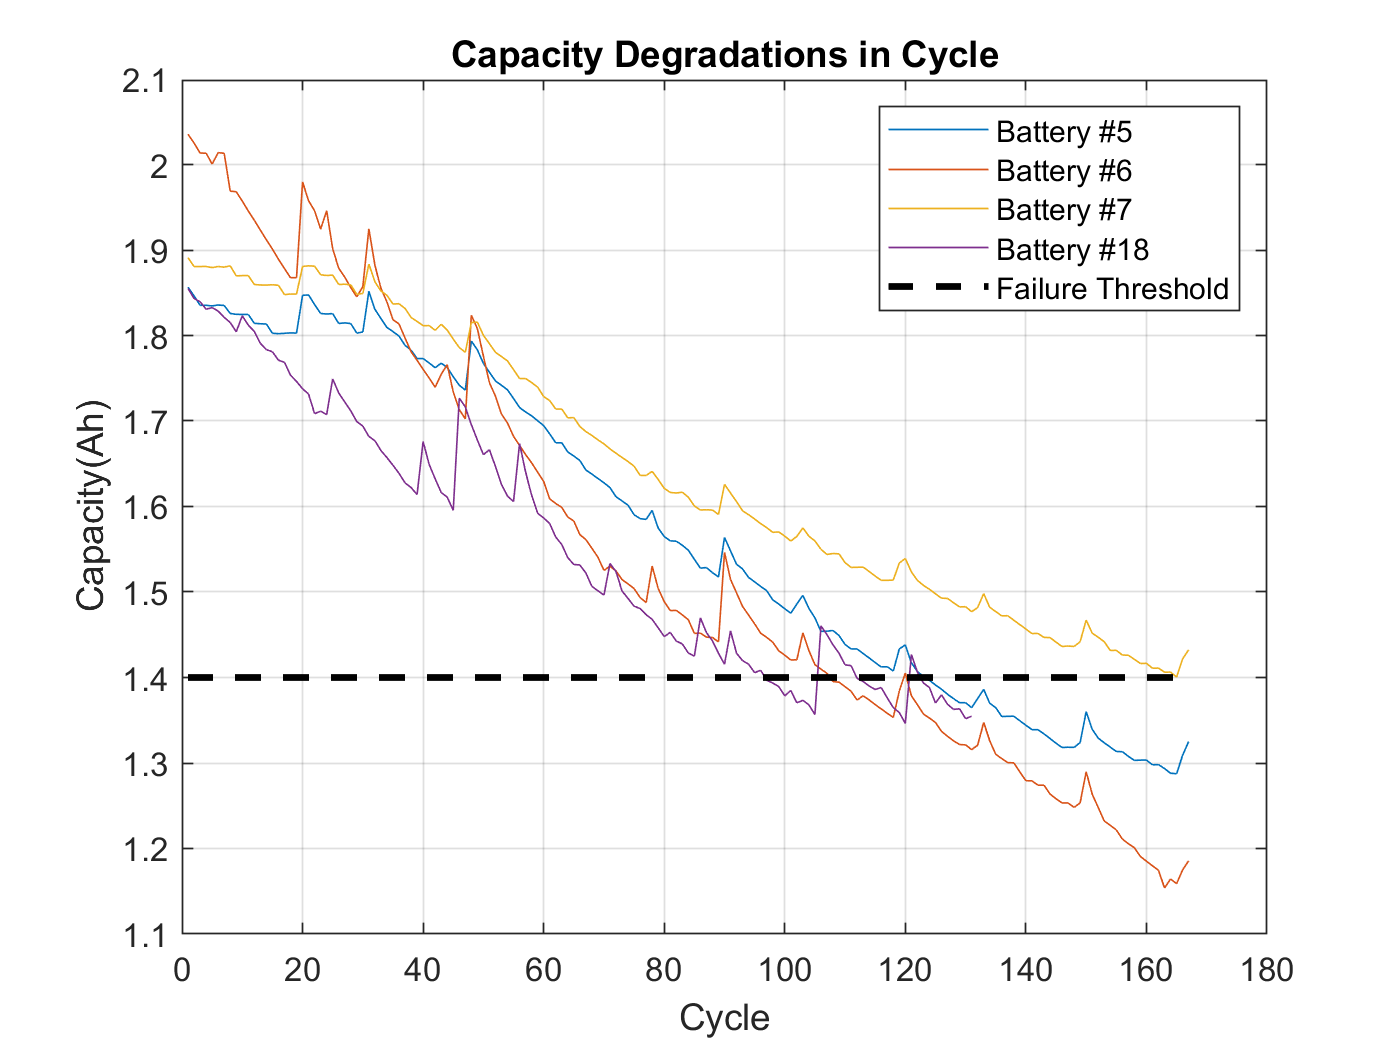


result = [ result5 ; result6 ; result7 ; result18];
%% org graph - cycle
cycle_number = length(capacity5);



result = [ result5 ; result6 ; result7 ; result18];
%% org graph - cycle
cycle_number = length(capacity5);

figure
plot(capacity5), hold on, plot(capacity6), plot(capacity7), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

#6 index 53 (58) 

#5 index 58 (64) 

에서 1.70으로 겹친다.

여기서 두개의 데이타 셋을 만든다.

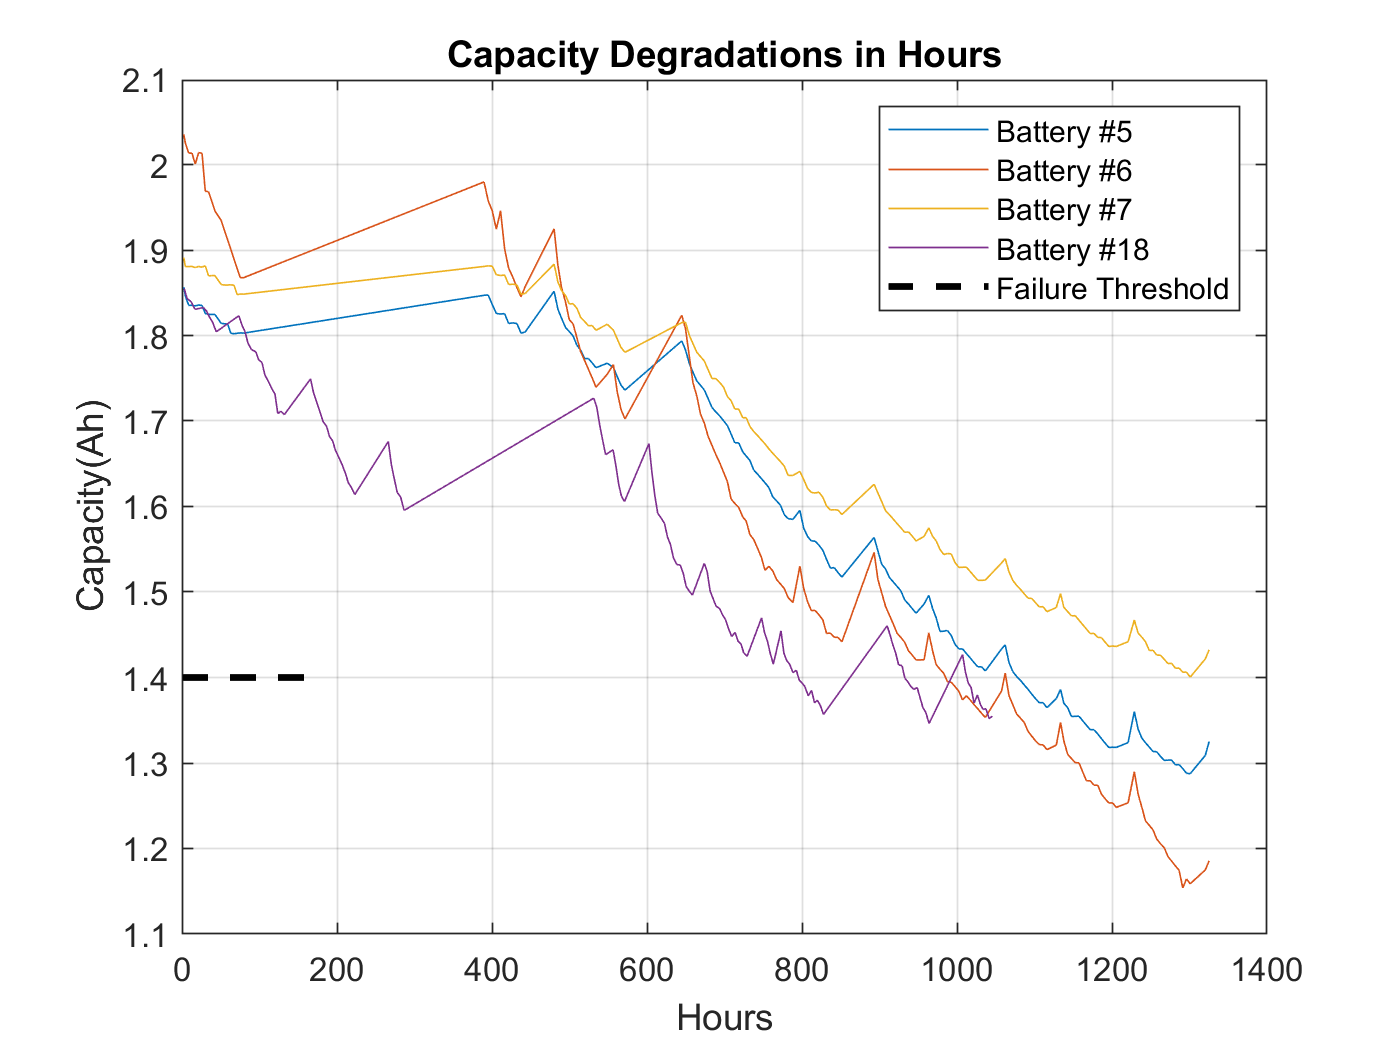

%% org graph -  time 
figure
plot(cycleTime5,capacity5), hold on, plot(cycleTime6,capacity6), plot(cycleTime7,capacity7), plot(cycleTime18,capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Hours, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Hours')

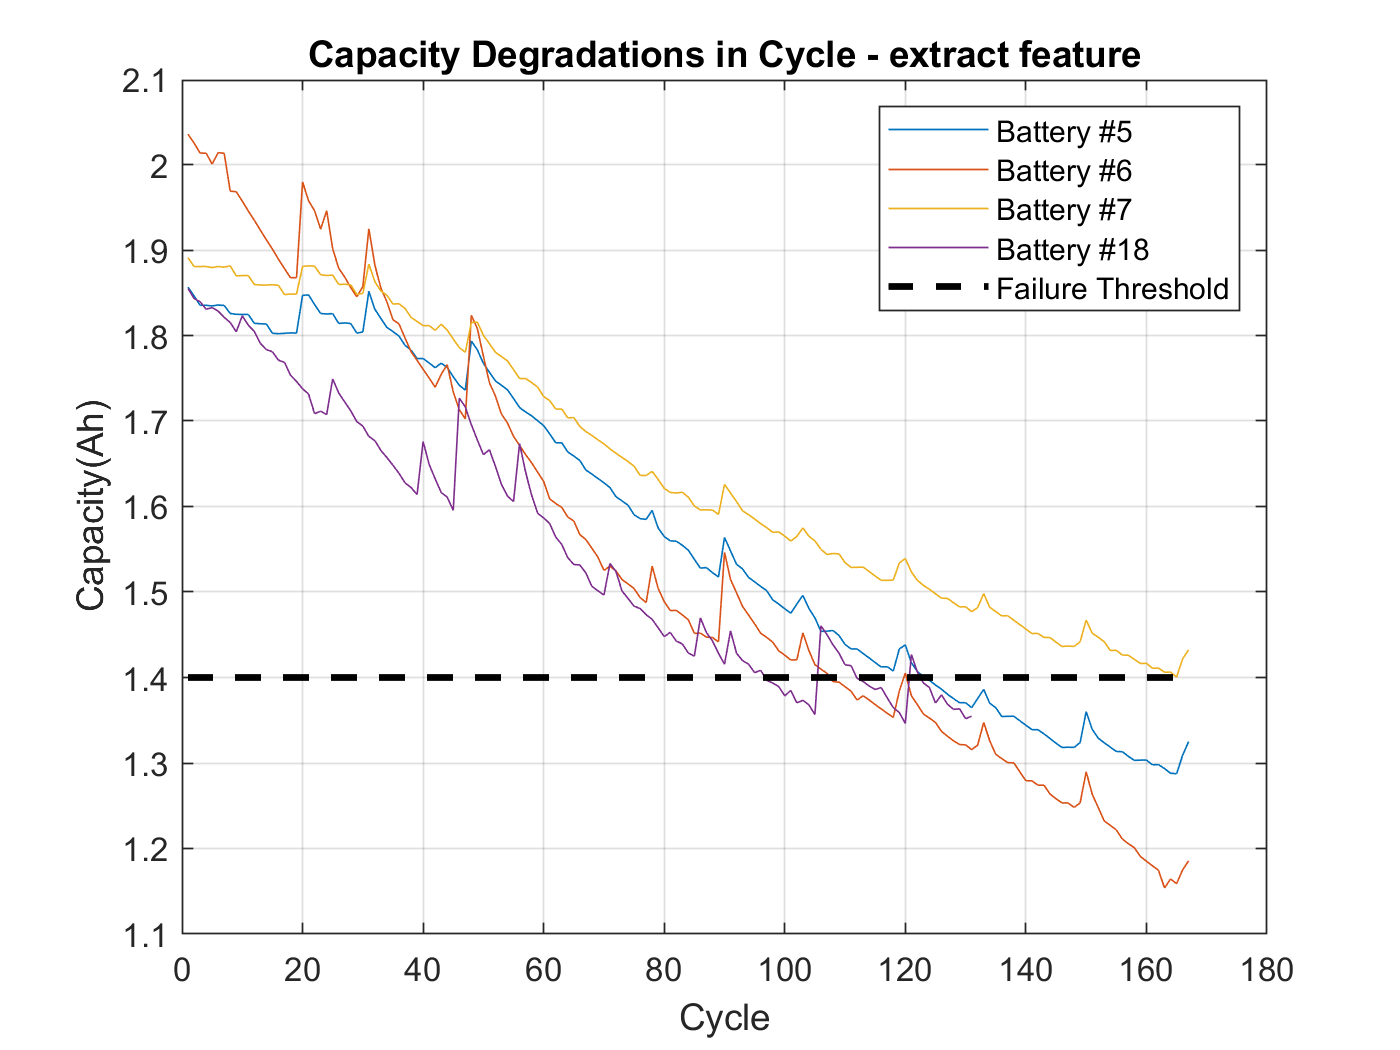


%% new graph using my function - cycle
figure
plot(capacity5), hold on, plot(capacity6), plot(capacity7), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle - extract feature')

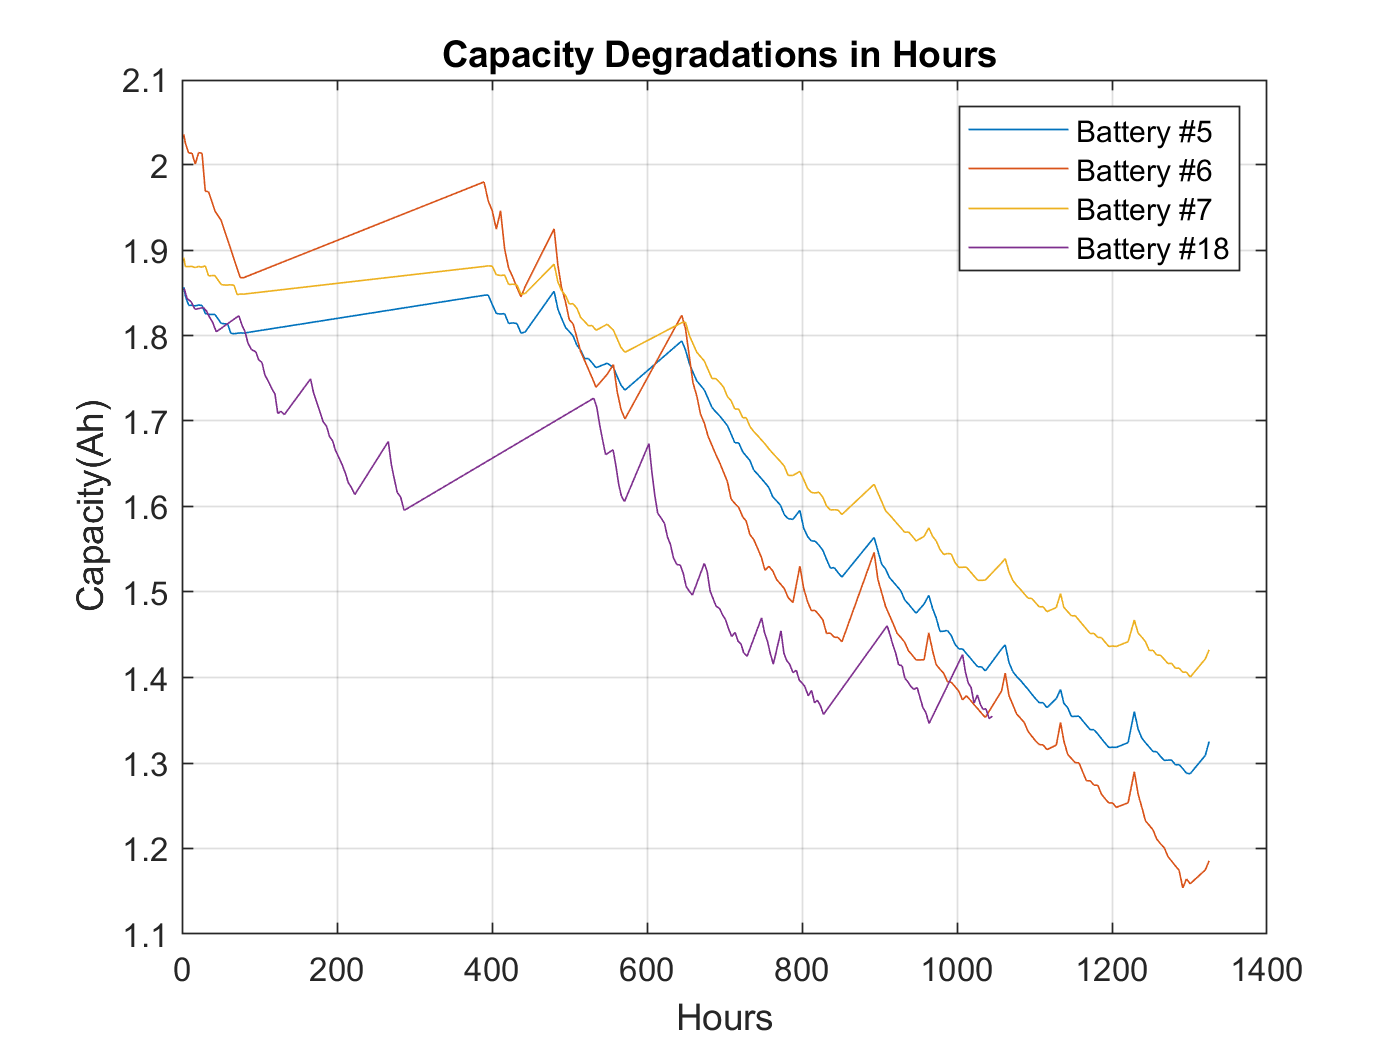


%% new graph using my function - time
figure
plot(cycleTime5,capacity5), hold on, plot(cycleTime6,capacity6), plot(cycleTime7,capacity7), plot(cycleTime18,capacity18)
hold off, grid on
xlabel Hours, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18')
title('Capacity Degradations in Hours ')

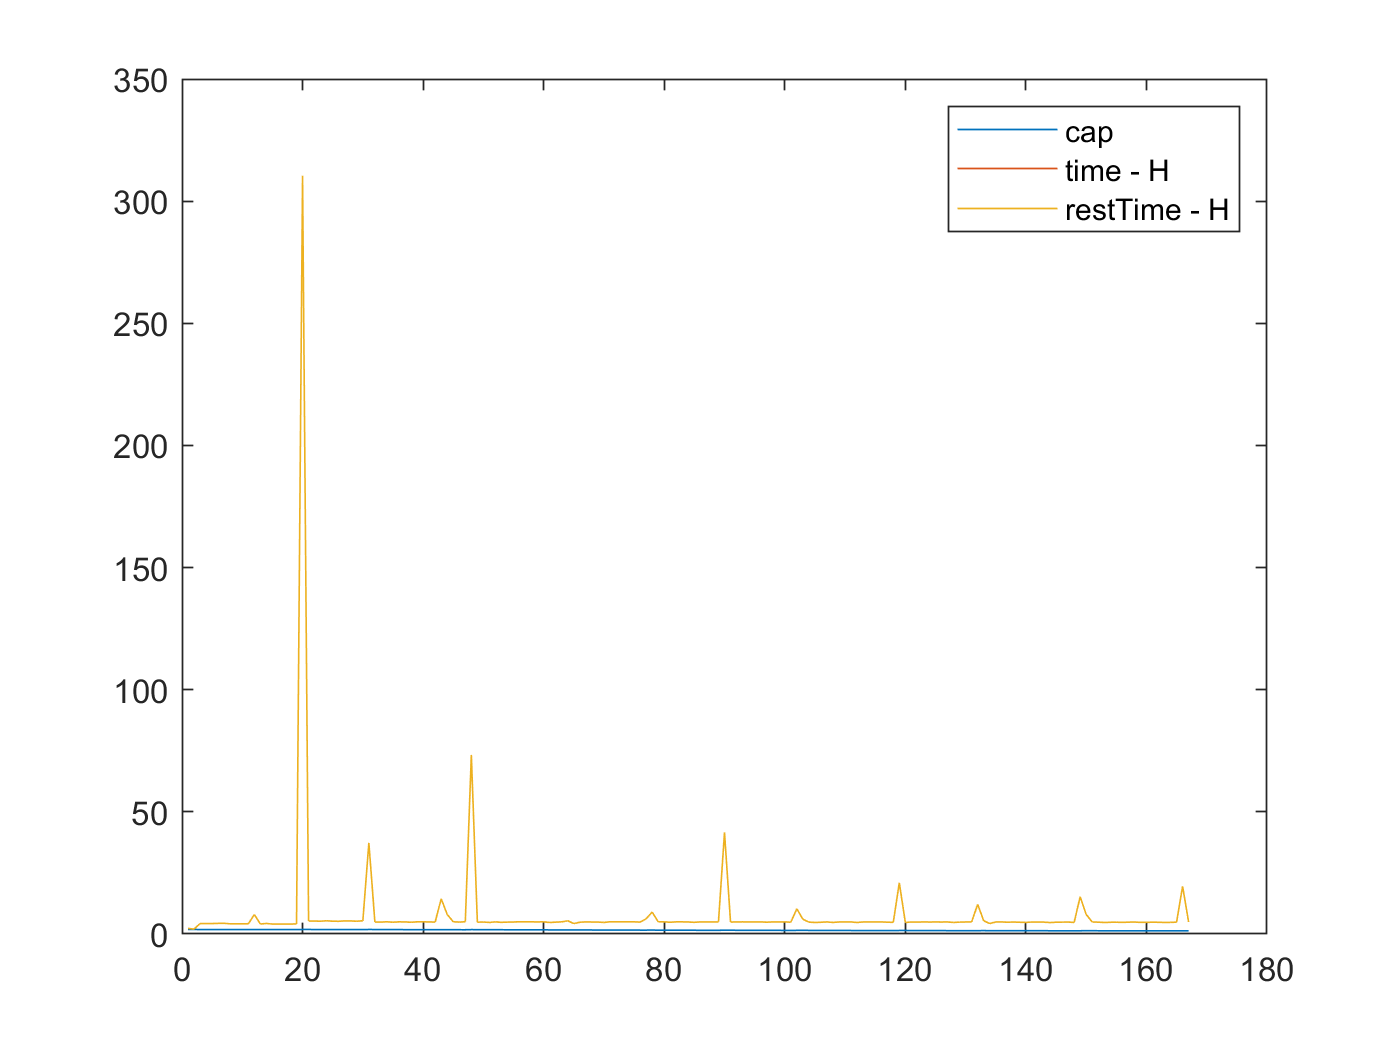

%% check outlier
%% check rest time
% https://kr.mathworks.com/matlabcentral/answers/15672-vector-shift
a = result5(:,1);
b = result5(:,2);
c = zeros(size(b));
n=1; %Shift units
c(n+1:end)=b(1:end-n);
c(1)=0;
d = b - c;
e = result5(:,3);
figure
plot(a)
hold on
plot(d)
plot(e)
legend('cap','time - H ','restTime - H')

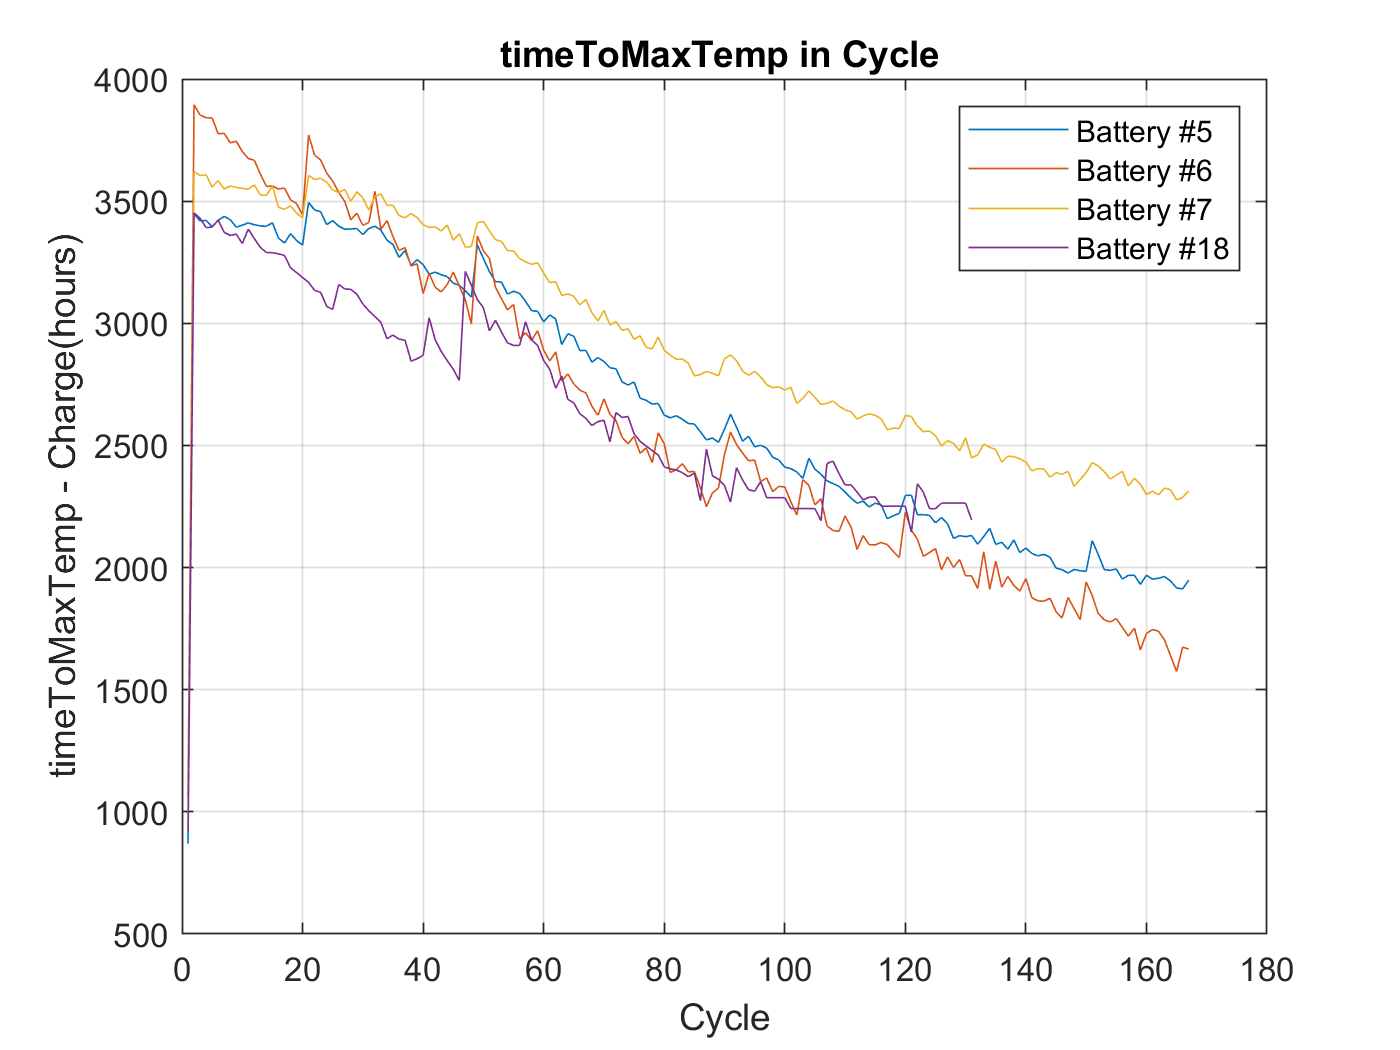


% result = [cap',cycleTime',restTime',restCycle',cTempMax',cTempMaxDt',cTempMaxDtAdj',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dTempMaxDtAdj' ];

figure
plot(cTempMaxDt5), hold on,plot(cTempMaxDt6),plot(cTempMaxDt7),plot(cTempMaxDt18),hold off, grid on
xlabel Cycle, ylabel 'timeToMaxTemp - Charge(hours)'
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('timeToMaxTemp in Cycle ')

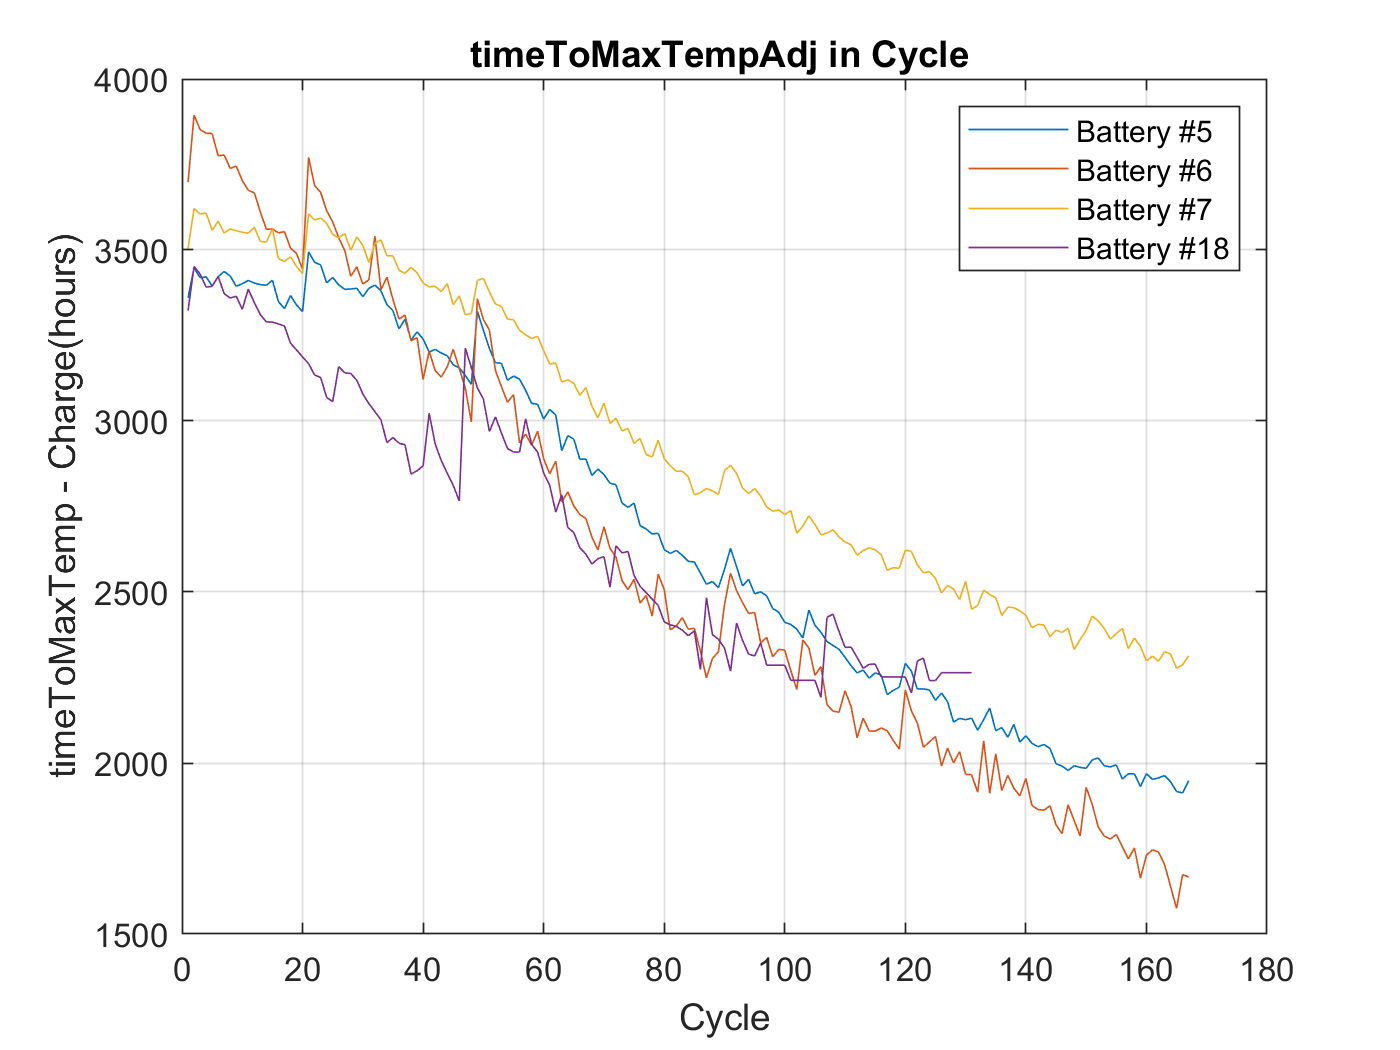


figure
plot(cTempMaxDtAdj5), hold on,plot(cTempMaxDtAdj6),plot(cTempMaxDtAdj7),plot(cTempMaxDtAdj18),hold off, grid on
xlabel Cycle, ylabel 'timeToMaxTemp - Charge(hours)'
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('timeToMaxTempAdj in Cycle ')

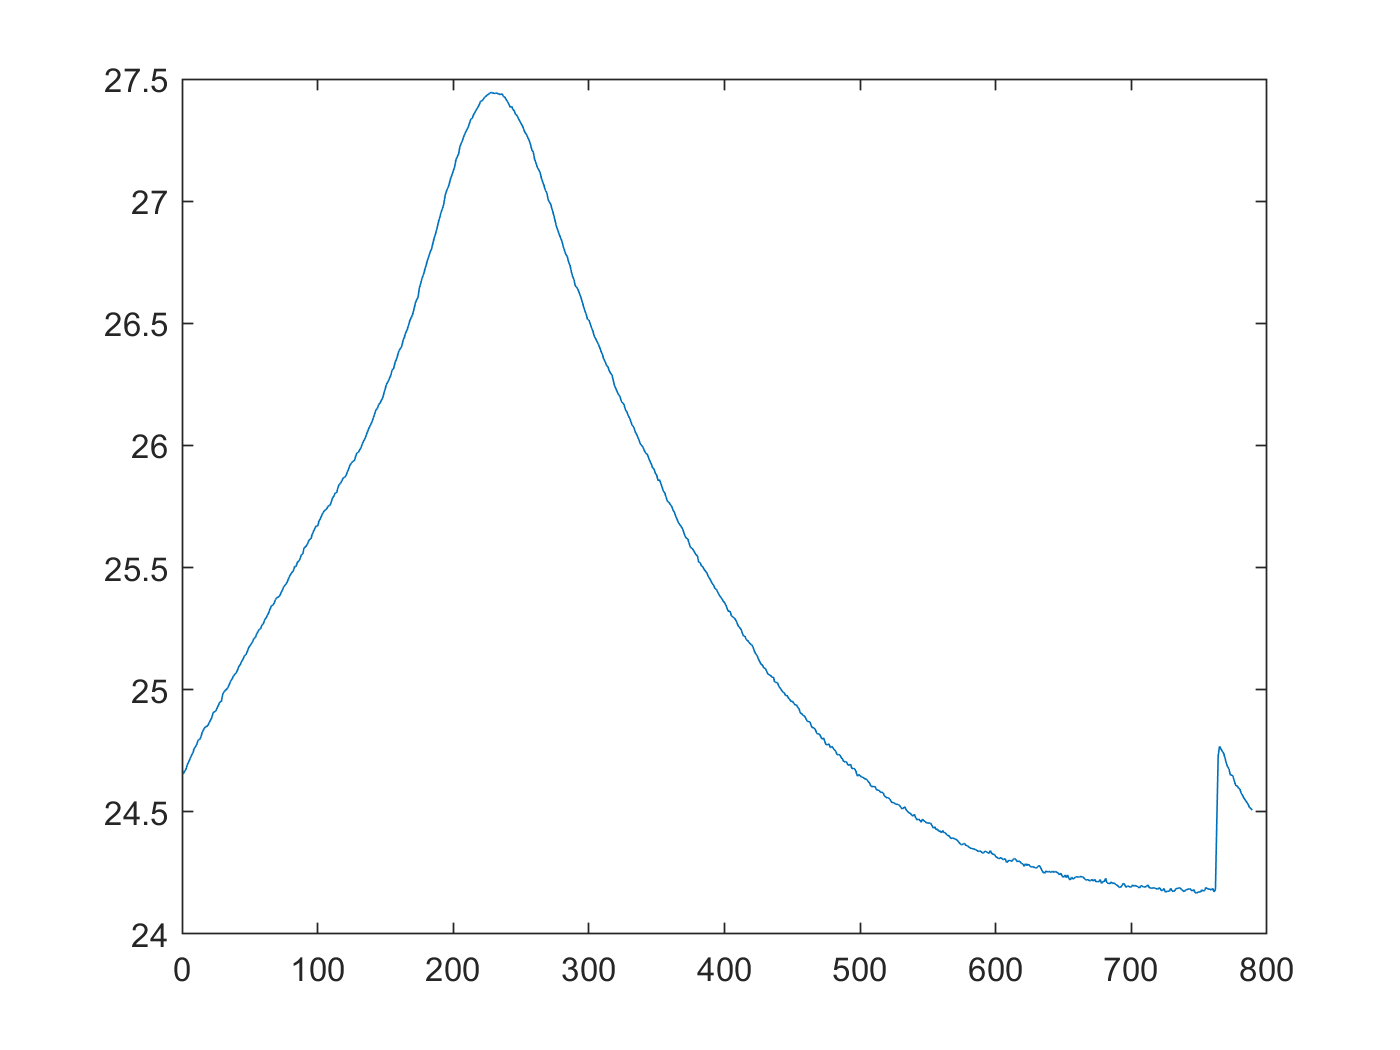


%result = [cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ];
%[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ] ...
    %= extract_raw_data(B0005,1);
[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload ] ...
    = extract_raw_data(B0005,1);

figure
plot(cTemp)

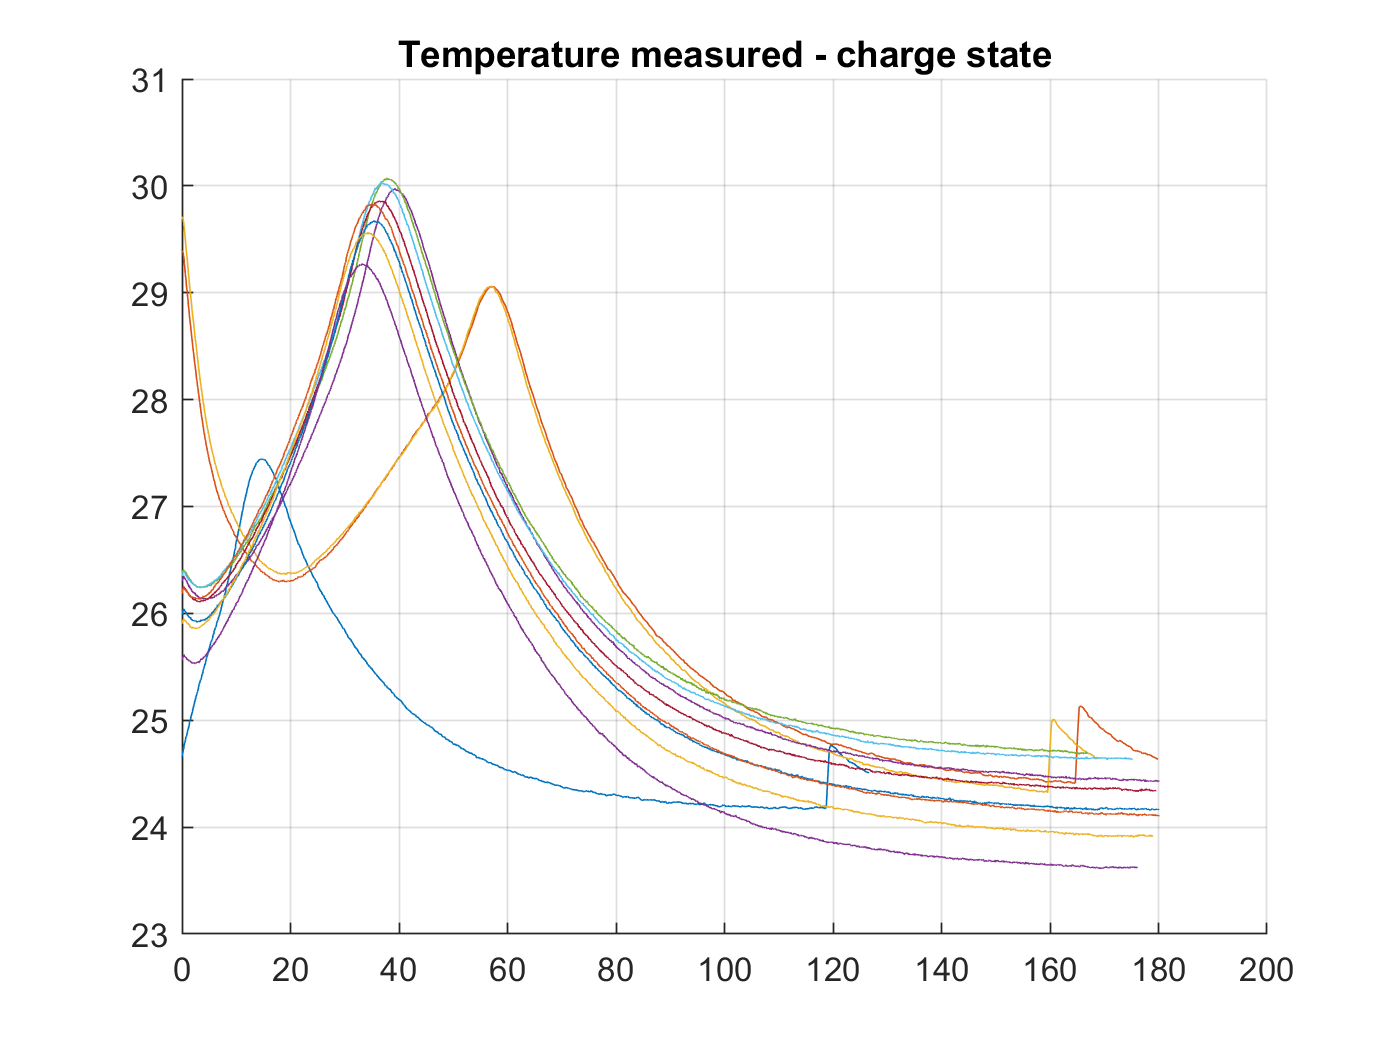



figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured - charge state")
grid on

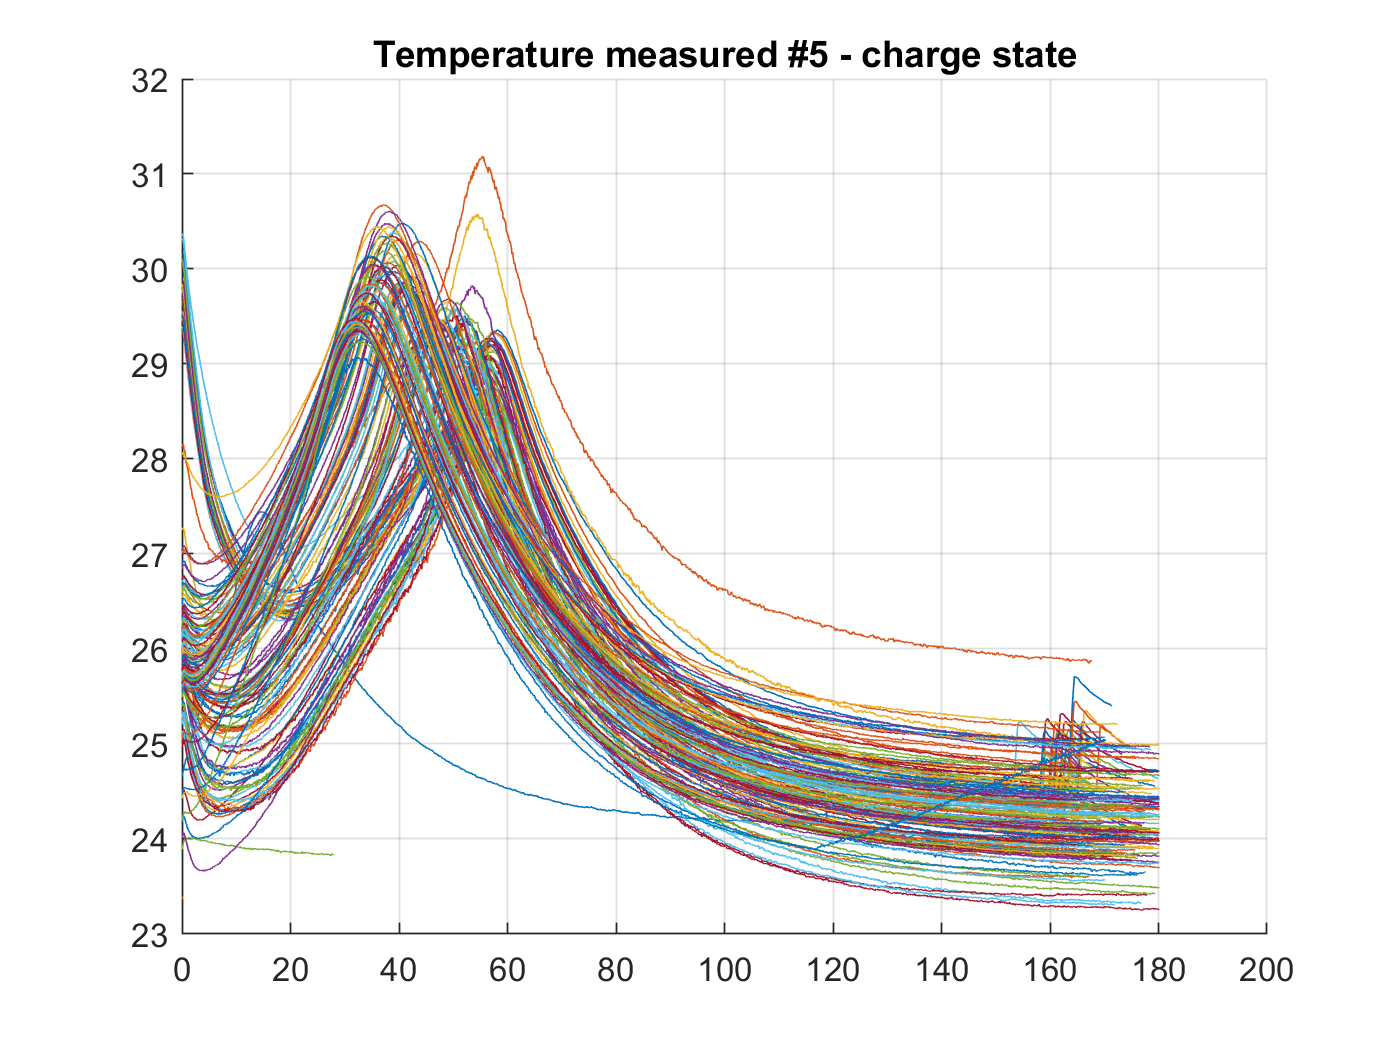


% https://kr.mathworks.com/matlabcentral/fileexchange/21050-varycolor
% https://blogs.mathworks.com/pick/2008/08/15/colors-for-your-multi-line-plots/?from=kr

items = size(B0005.cycle,2);

figure
ColorSet = varycolor(items);
hold all;
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        %end
    end
end
hold off 
title("Temperature measured #5 - charge state")
grid on


temp_B18_19 = B0018.cycle(19).data.Temperature_measured

temp_B18_19 =    36.1867   36.1535   36.1301   36.1127   36.0760   36.0429   36.0002   35.9569   35.9040   35.8626   35.8118   35.7616   35.7143   35.6644   35.6151   35.5730   35.5239   35.4833   35.4340   35.3837   35.3436   35.2929   35.2360   35.1931   35.1531   35.1061   35.0537   35.0122   34.9617   34.9027   34.8544   34.8043   34.7614   34.7192   34.6788   34.6349   34.5852   34.5412   34.4930   34.4541   34.3987   34.3659   34.3115   34.2694   34.2279   34.1767   34.1279   34.0850   34.0493   34.0011


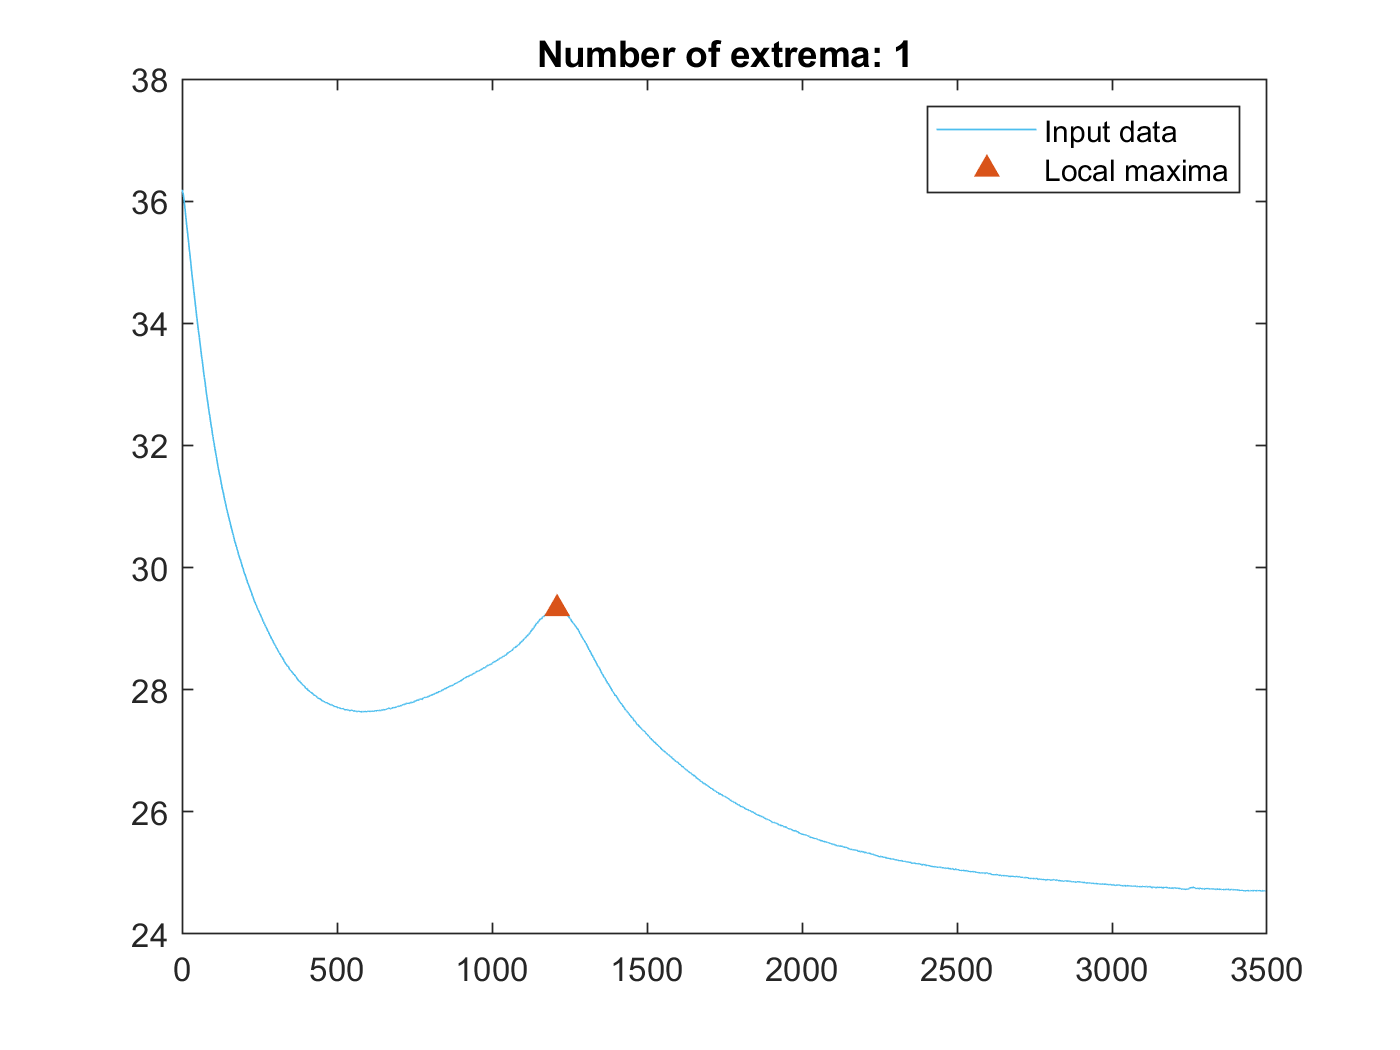

% Find local maxima
maxIndices = islocalmax(temp_B18_19,"MinProminence",1.5);

% Display results
clf
plot(temp_B18_19,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices),temp_B18_19(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend


items = size(B0018.cycle,2);
cTempMaxIndex = [];


figure
ColorSet = varycolor(items);
hold all;
k=1

k = 1

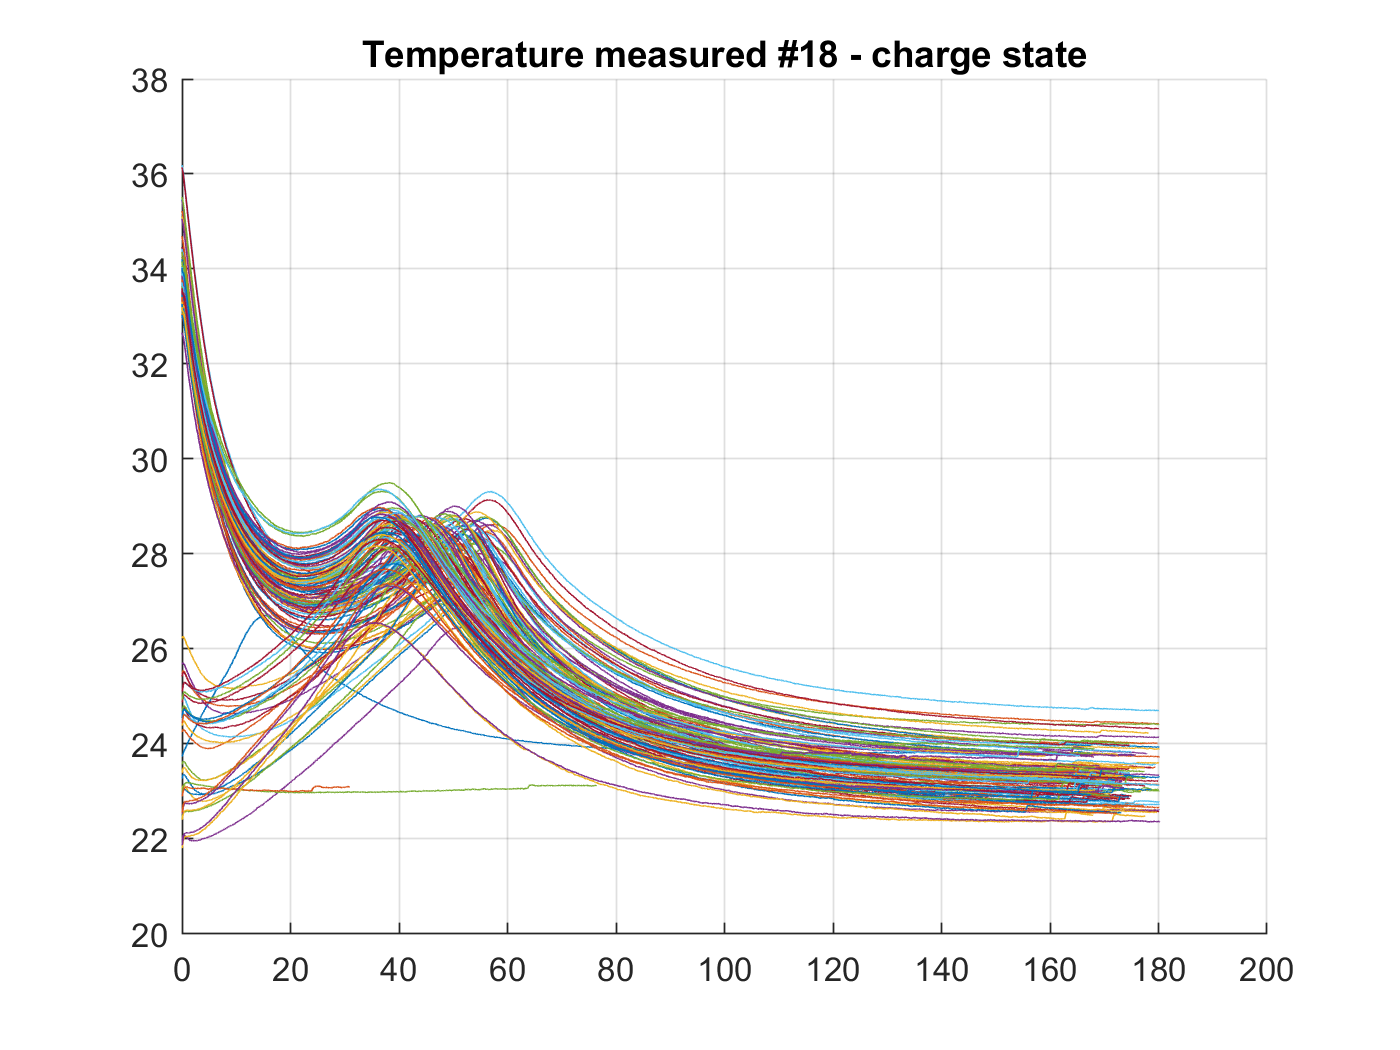

for i=1:items
    if isequal(B0018.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            %k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60, B0018.cycle(i).data.Temperature_measured)
            temp = B0018.cycle(i).data.Temperature_measured;
            cTempMaxGuess = islocalmax(temp,'MinProminence',2);
            if sum(cTempMaxGuess(:) == 1 ) == 0 
               cTempMaxGuess = islocalmax(temp,'MinProminence',1);
            end
            
            if sum(cTempMaxGuess(:) == 1 ) == 0 
                smoothed = smoothdata(B0018.cycle(i).data.Temperature_measured);
                cTempMaxGuess = islocalmax(smoothed,'MinProminence',2);
                if sum(cTempMaxGuess(:) == 1 ) == 0 
                   cTempMaxGuess = islocalmax(smoothed,'MinProminence',1);
                end
            end

            if sum(cTempMaxGuess(:) == 1 ) == 0 
                cTempMaxIndex(k) = max(temp);            
            else 
                cTempMaxIndex(k) = find(cTempMaxGuess, 1, 'first');  
            end
            k = k+1;
        %end
    end
end
hold off 
title("Temperature measured #18 - charge state")
grid on

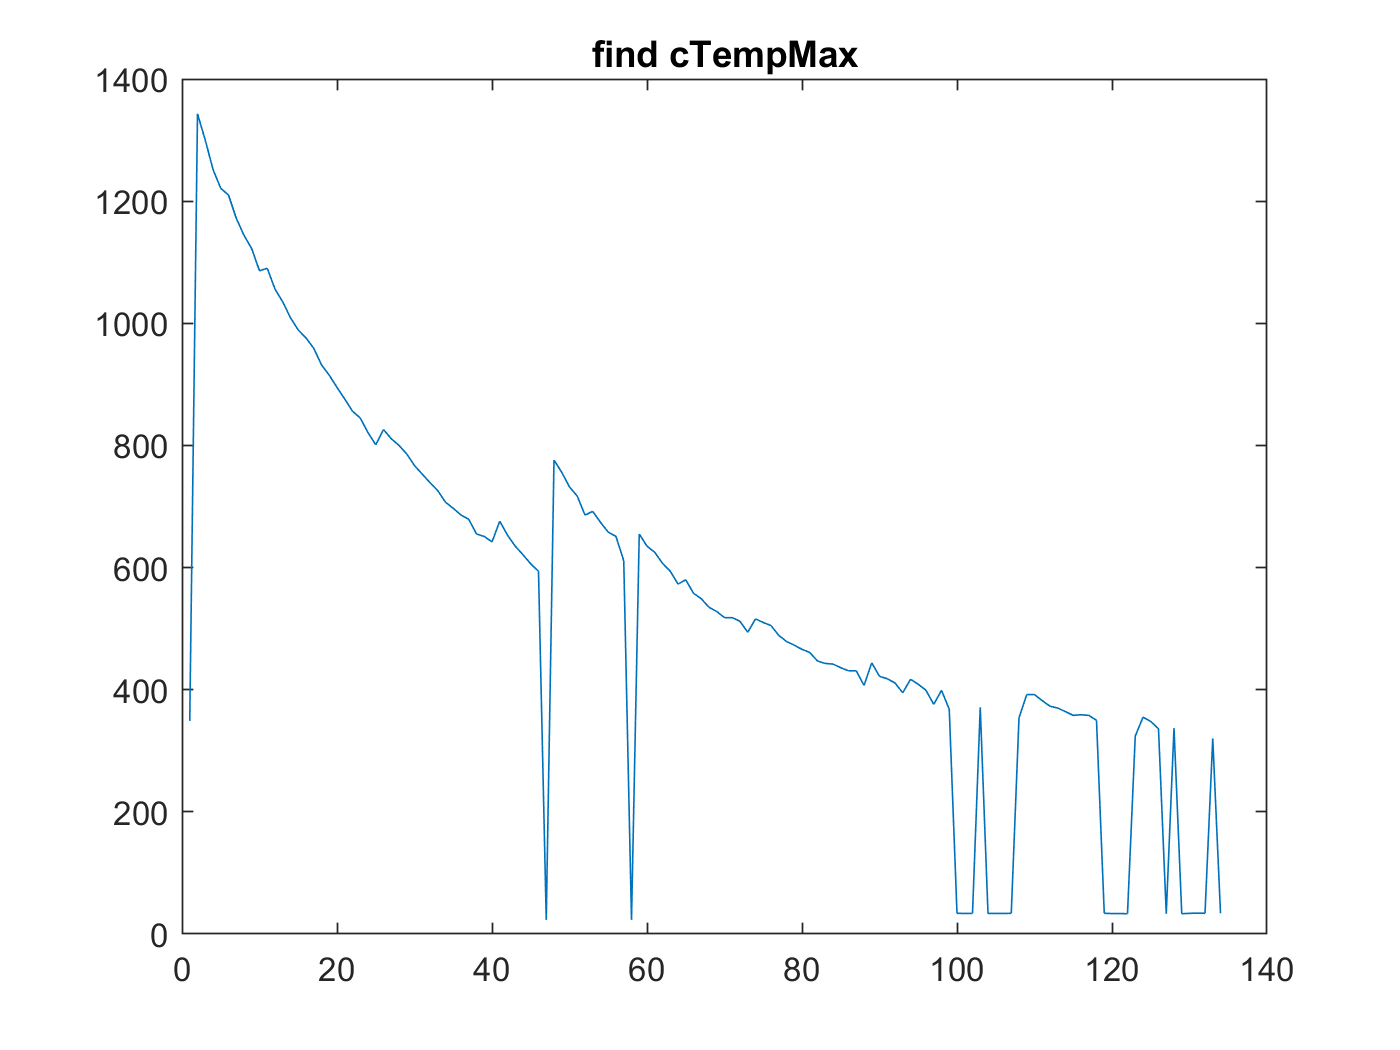

figure
%plot(cTempMaxGuess)
%hold on
%yyaxis("right")
plot(cTempMaxIndex)
hold off
title("find cTempMax")


              
cTempMaxDt = cTempMaxDt18;
cTempMaxDtAdj = cTempMaxDtAdj18;

% https://kr.mathworks.com/help/matlab/ref/isoutlier.html
cTempMaxDt_outliear = isoutlier(cTempMaxDt);
% https://kr.mathworks.com/matlabcentral/answers/37196-count-number-of-specific-values-in-matrix
sum(cTempMaxDt_outliear(:) == 1)

ans = 1

cTempMaxDt_outliear_mean = isoutlier(cTempMaxDt,'mean');
sum(cTempMaxDt_outliear_mean(:) == 1)

ans = 1

cTempMaxDt_outliear_sw2 = isoutlier(cTempMaxDt,'movmedian',2,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw2(:) == 1)

ans = 0

cTempMaxDt_outliear_sw2_fix = filloutliers(cTempMaxDt,'clip','movmedian',2,'SamplePoints',1:length(cTempMaxDt));

cTempMaxDt_outliear_sw3 = isoutlier(cTempMaxDt,'movmedian',3,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw3(:) == 1)

ans = 3

cTempMaxDt_outliear_sw3_fix = filloutliers(cTempMaxDt,'clip','movmedian',3,'SamplePoints',1:length(cTempMaxDt));

cTempMaxDt_outliear_sw5 = isoutlier(cTempMaxDt,'movmedian',5,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw5(:) == 1)

ans = 7

cTempMaxDt_outliear_sw5_fix = filloutliers(cTempMaxDt,'clip','movmedian',5,'SamplePoints',1:length(cTempMaxDt));

cTempMaxDt_outliear_sw7 = isoutlier(cTempMaxDt,'movmedian',7,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw7(:) == 1)

ans = 11

cTempMaxDt_outliear_sw7_fix = filloutliers(cTempMaxDt,'clip','movmedian',7,'SamplePoints',1:length(cTempMaxDt));

cTempMaxDt_outliear_sw9 = isoutlier(cTempMaxDt,'movmedian',9,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw9(:) == 1)

ans = 11

cTempMaxDt_outliear_sw9_fix = filloutliers(cTempMaxDt,'clip','movmedian',9,'SamplePoints',1:length(cTempMaxDt));

cTempMaxDt_outliear_sw11 = isoutlier(cTempMaxDt,'movmedian',11,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw11(:) == 1)

ans = 6

cTempMaxDt_outliear_sw11_fix = filloutliers(cTempMaxDt,'clip','movmedian',11,'SamplePoints',1:length(cTempMaxDt));


cTempMaxDt_outliear_sw21 = isoutlier(cTempMaxDt,'movmedian',21,'SamplePoints',1:length(cTempMaxDt));
sum(cTempMaxDt_outliear_sw21(:) == 1)

ans = 3

cTempMaxDt_outliear_sw21_fix = filloutliers(cTempMaxDt,'clip','movmedian',21,'SamplePoints',1:length(cTempMaxDt));



cTempMaxDtAdj_outliear = isoutlier(cTempMaxDtAdj);
% https://kr.mathworks.com/matlabcentral/answers/37196-count-number-of-specific-values-in-matrix
sum(cTempMaxDtAdj_outliear(:) == 1)

ans = 0

cTempMaxDtAdj_outliear_mean = isoutlier(cTempMaxDtAdj,'mean');
sum(cTempMaxDtAdj_outliear_mean(:) == 1)

ans = 0

cTempMaxDtAdj_outliear_sw = isoutlier(cTempMaxDtAdj,'movmedian',5,'SamplePoints',1:length(cTempMaxDtAdj));
sum(cTempMaxDtAdj_outliear_sw(:) == 1)

ans = 6

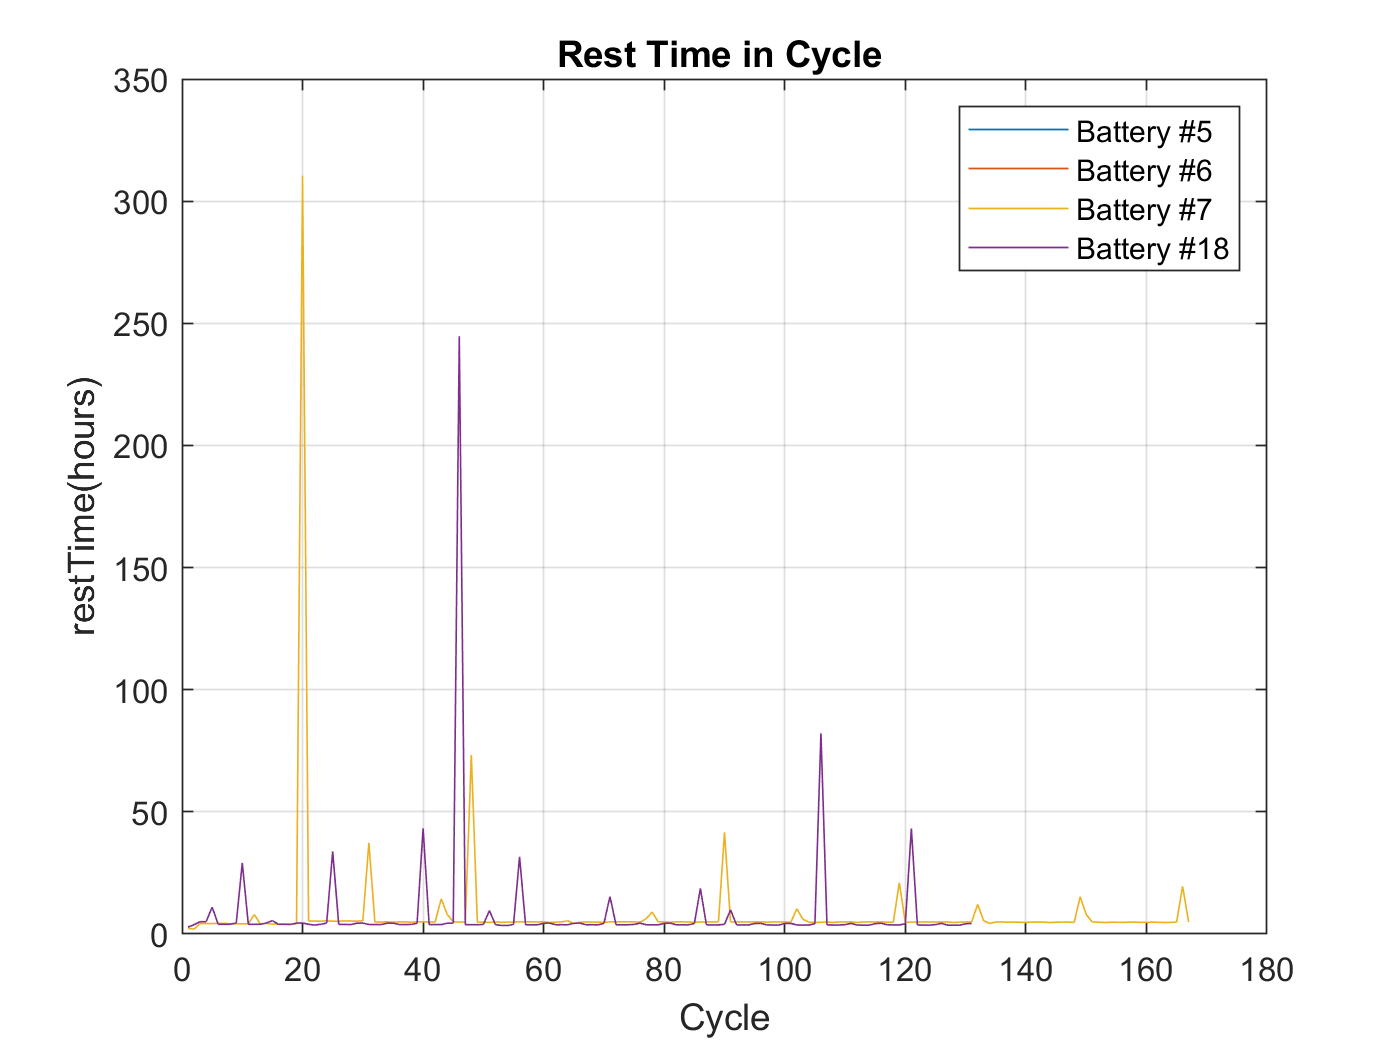



%% rest time   - cycle
use_plot = true; %false;
% battery 18번이 한번 큰 rest time을 가져서 그래프로 보기 힘들다.
figure
if use_plot
    %plot(restTime5), hold on, plot(restTime6), plot(restTime7)
    % plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
    plot(restTime5), hold on, plot(restTime6), plot(restTime7),plot(restTime18)
else
    bar(restTime5), hold on, bar(restTime6), bar(restTime7),bar(restTime18)
end
hold off, grid on
xlabel Cycle, ylabel restTime(hours)
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('Rest Time in Cycle ')

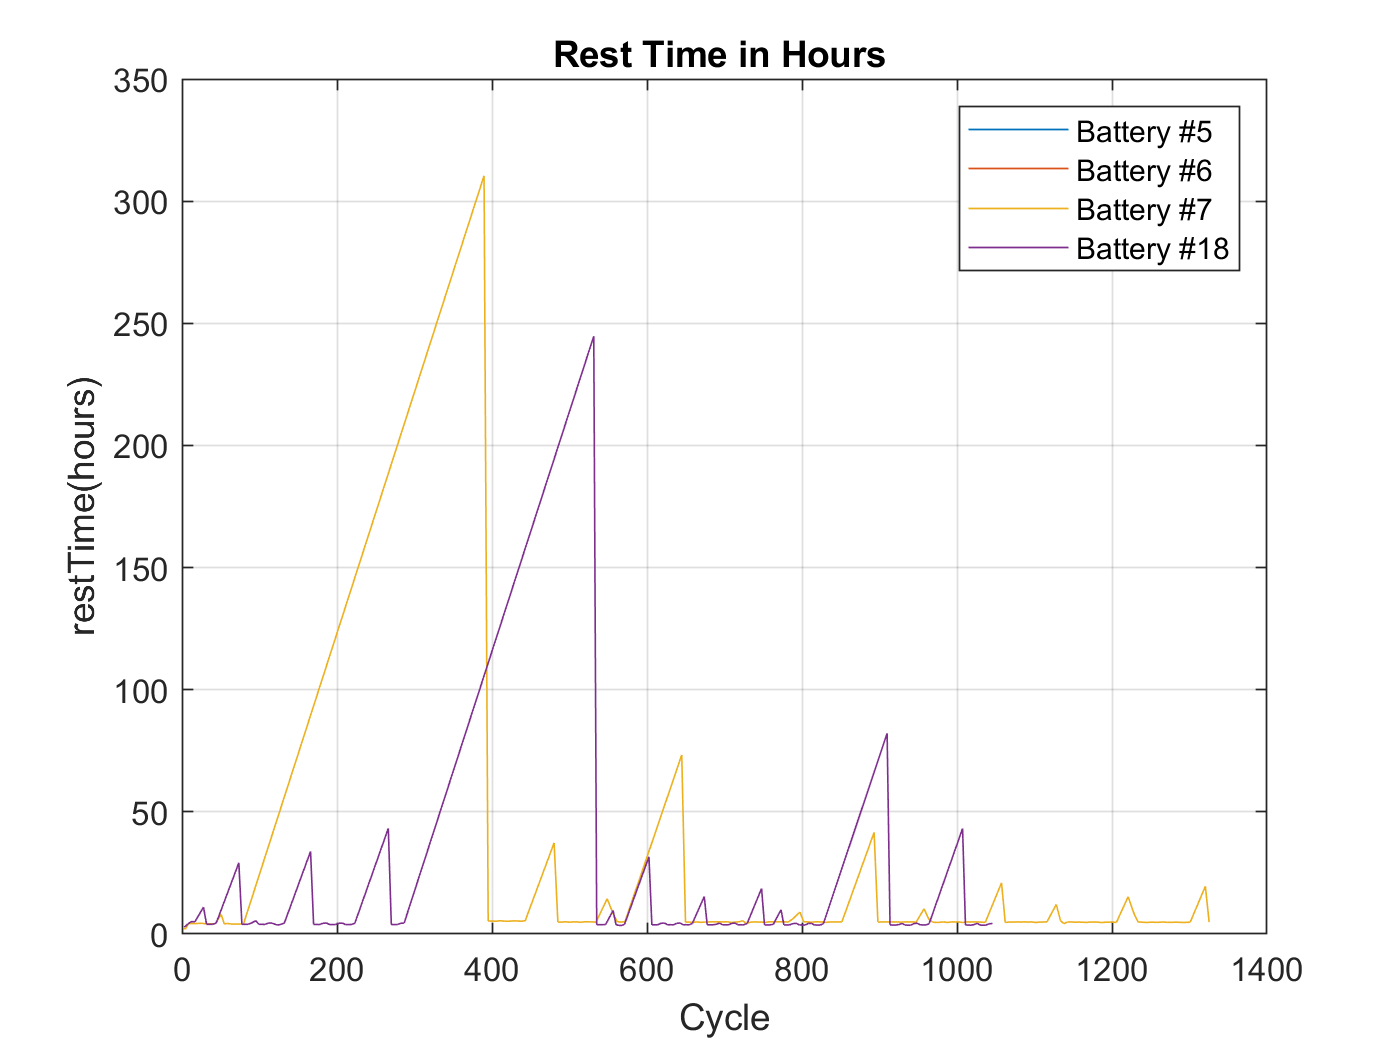


%% rest time   - time
figure
if use_plot
    %plot(cycleTime5,restTime5), hold on, plot(cycleTime6,restTime6), plot(cycleTime7,restTime7)
    % plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
    plot(cycleTime5,restTime5), hold on, plot(cycleTime6,restTime6), plot(cycleTime7,restTime7),plot(cycleTime18,restTime18)
else
    bar(cycleTime5,restTime5), hold on, bar(cycleTime6,restTime6), bar(cycleTime7,restTime7),bar(cycleTime18,restTime18)
end 
hold off, grid on
xlabel Cycle, ylabel restTime(hours)
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18')
title('Rest Time in Hours ')

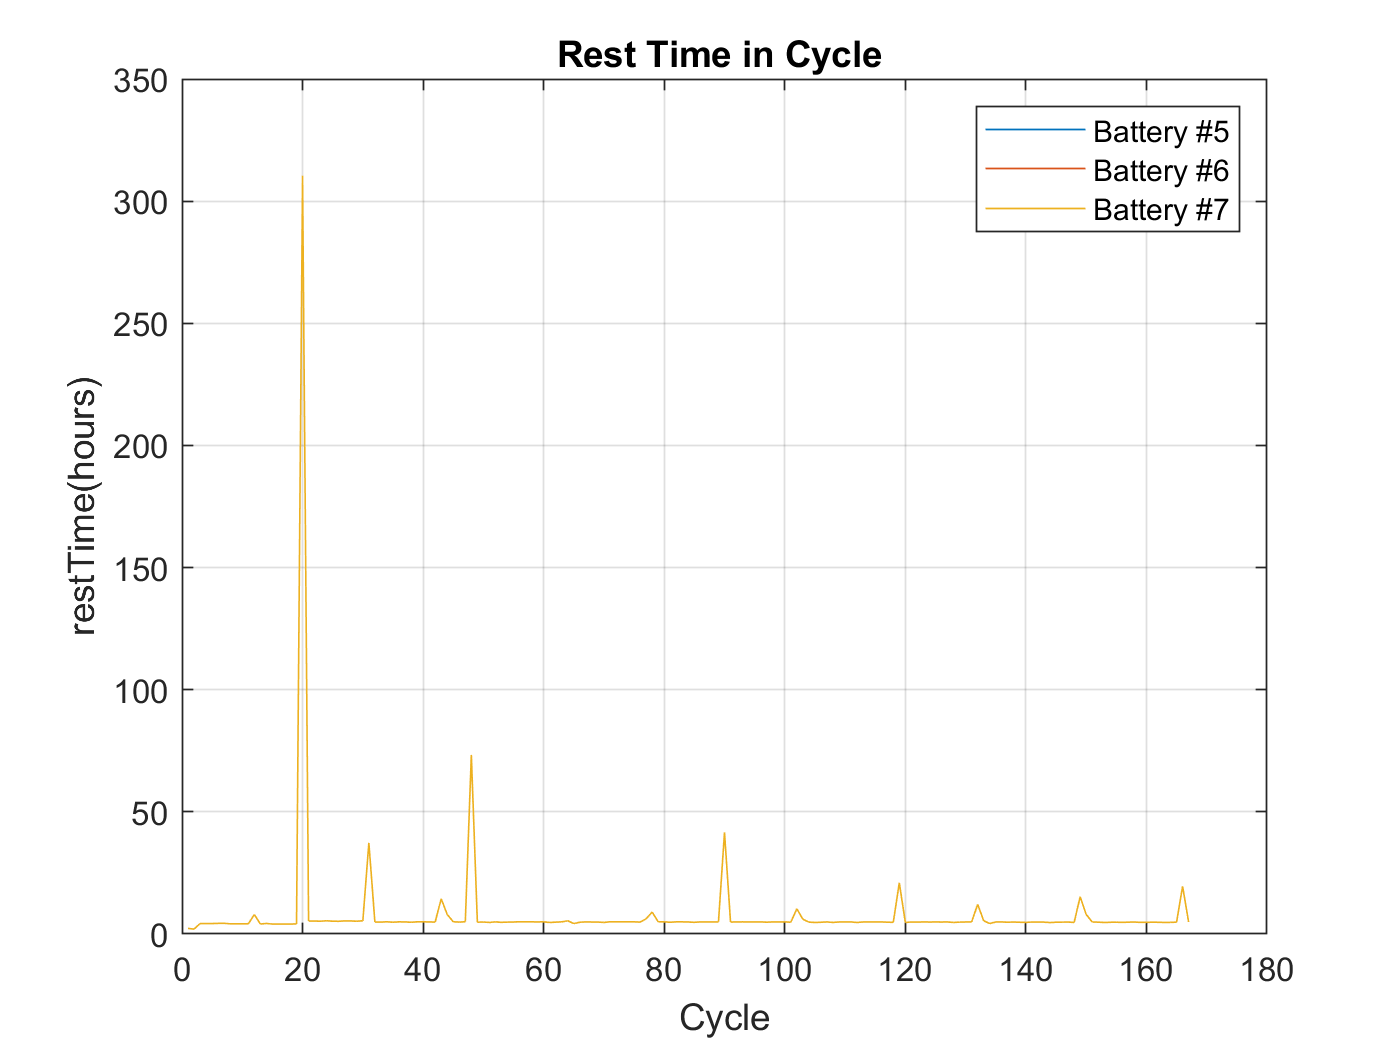



%% remove battery 18 

figure

plot(restTime5), hold on, plot(restTime6), plot(restTime7)
hold off, grid on
xlabel Cycle, ylabel restTime(hours)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Rest Time in Cycle ')

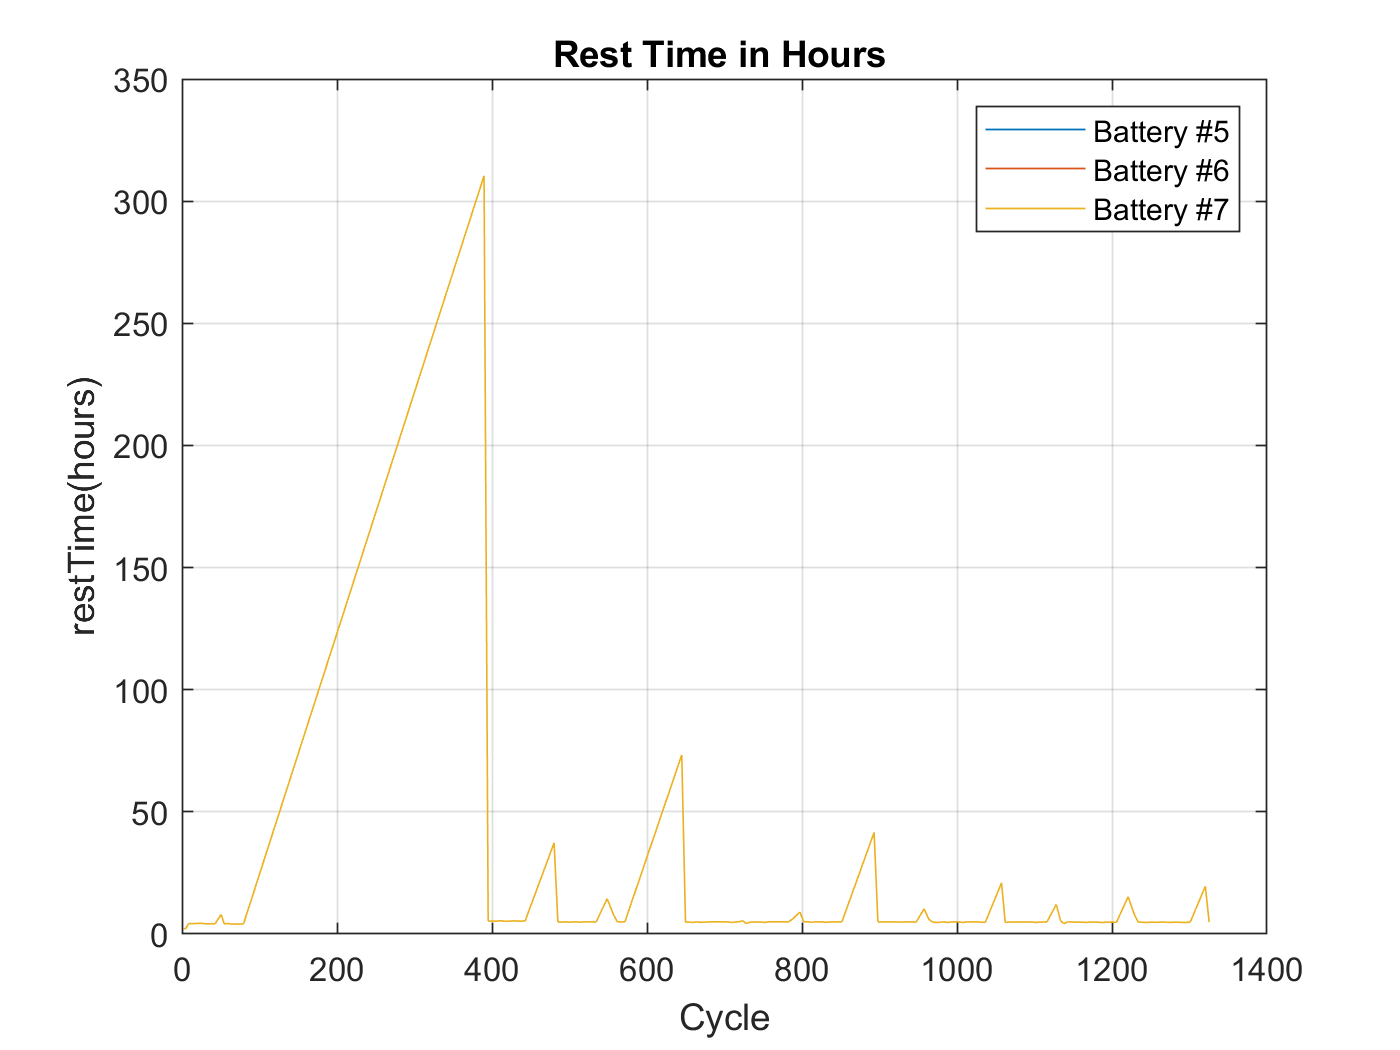


figure
plot(cycleTime5,restTime5), hold on, plot(cycleTime6,restTime6), plot(cycleTime7,restTime7)
hold off, grid on
xlabel Cycle, ylabel restTime(hours)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Rest Time in Hours ')


%% index
i=1;
capacityIdx = i; i=i+1;
cycleTimeIdx = i; i=i+1;
restTimeIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cTempMaxDtIdx = i; i=i+1;
cTempMaxDtAdjIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dTempMaxDtIdx = i; i=i+1;idxResult = i; i=i+1;
dTempMaxDtAdjIdx = i; i=i+1;

%% create vector / table
    
regression_vector5 = [ ...
    result5(:, restTimeIdx ) ... 
    result5(:, cTempMaxDtAdjIdx ) ...
    result5(:, ohmIdx ) ...
    result5(:, pattern_dVoltIdx ) ...
    result5(:, capacityIdx ) ] ;

regression_vector6 = [ ...
    result6(:, restTimeIdx ) ... 
    result6(:, cTempMaxDtAdjIdx ) ...
    result6(:, ohmIdx ) ...
    result6(:, pattern_dVoltIdx ) ...
    result6(:, capacityIdx ) ] ;

regression_vector7 = [ ...
    result7(:, restTimeIdx ) ... 
    result7(:, cTempMaxDtAdjIdx ) ...
    result7(:, ohmIdx ) ...
    result7(:, pattern_dVoltIdx ) ...
    result7(:, capacityIdx ) ] ;

regression_vector18 = [ ...
    result18(:, restTimeIdx ) ... 
    result18(:, cTempMaxDtAdjIdx ) ...
    result18(:, ohmIdx ) ...
    result18(:, pattern_dVoltIdx ) ...
    result18(:, capacityIdx ) ] ;

regression_vector = [ ...
    result(:, restTimeIdx ) ... 
    result(:, cTempMaxDtAdjIdx ) ...
    result(:, ohmIdx ) ...
    result(:, pattern_dVoltIdx ) ...
    result(:, capacityIdx ) ] ;

regression_vector_5_6 = [ ...
    result_5_6(:, restTimeIdx ) ... 
    result_5_6(:, cTempMaxDtAdjIdx ) ...
    result_5_6(:, ohmIdx ) ...
    result_5_6(:, pattern_dVoltIdx ) ...
    result_5_6(:, capacityIdx ) ] ;

regression_vector5_6 = [ ...
    result5_6(:, restTimeIdx ) ... 
    result5_6(:, cTempMaxDtAdjIdx ) ...
    result5_6(:, ohmIdx ) ...
    result5_6(:, pattern_dVoltIdx ) ...
    result5_6(:, capacityIdx ) ] ;

regression_vector6_5 = [ ...
    result6_5(:, restTimeIdx ) ... 
    result6_5(:, cTempMaxDtAdjIdx ) ...
    result6_5(:, ohmIdx ) ...
    result6_5(:, pattern_dVoltIdx ) ...
    result6_5(:, capacityIdx ) ] ;

% works
regression_table5 = array2table(regression_vector5,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table6 = array2table(regression_vector6,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table5_6 = array2table(regression_vector5_6,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table6_5 = array2table(regression_vector6_5,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table_5_6 = array2table(regression_vector_5_6,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table7 = array2table(regression_vector7,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table18 = array2table(regression_vector18,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});

regression_table = array2table(regression_vector,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'});
    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector5,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','capacity'});

regression_table_6 = array2table(regression_vector6,...
    'VariableNames',{'restTime','cTempMaxDtAdj','ohm','capacity'});
%}


## corellaton

%{ 
% error after adding pattern_dVolt
figure
[R5,PValue5] = corrplot(regression_vector5,'type','Pearson','testR','on','varNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'})
figure
[R6,PValue6] = corrplot(regression_vector6,'type','Pearson','testR','on','varNames',{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt','capacity'})
%}

%% linear regression

% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' capacity ~ restTime + cTempMaxDtAdj + ohm + pattern_dVolt '

modelspec = ' capacity ~ restTime + cTempMaxDtAdj + ohm + pattern_dVolt '

modelspecSingleX = ' capacity ~  cTempMaxDtAdj + pattern_dVolt '

modelspecSingleX = ' capacity ~  cTempMaxDtAdj + pattern_dVolt '

mdl = fitlm(regression_table,modelspec )

mdl = Linear regression model:
    capacity ~ 1 + restTime + cTempMaxDtAdj + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue   
                     __________    __________    _______    ___________

    (Intercept)         0.58398      0.012831     45.513    7.1012e-201
    restTime         0.00043159    3.2125e-05     13.435     2.4102e-36
    cTempMaxDtAdj    0.00037841     2.396e-06     157.94              0
    ohm                  12.179        2.0054      6.073     2.1764e-09
    pattern_dVolt     -0.044854     0.0042887    -10.459     1.0458e-23


Number of observations: 632, Error degrees of freedom: 627
Root Mean Squared Error: 0.0193
R-squared: 0.991,  Adjusted R-Squared: 0.991
F-statistic vs

mdlSingleX = fitlm(regression_table,modelspecSingleX )

mdlSingleX = Linear regression model:
    capacity ~ 1 + cTempMaxDtAdj + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue   
                     __________    __________    _______    ___________

    (Intercept)         0.64701     0.0088562     73.057    1.7422e-309
    cTempMaxDtAdj    0.00036825    1.6616e-06     221.62              0
    pattern_dVolt     -0.042776      0.004896    -8.7369     2.1649e-17


Number of observations: 632, Error degrees of freedom: 629
Root Mean Squared Error: 0.0222
R-squared: 0.988,  Adjusted R-Squared: 0.988
F-statistic vs. constant model: 2.51e+04, p-value = 0


mdl5 = fitlm(regression_table5,modelspec )

mdl5 = Linear regression model:
    capacity ~ 1 + restTime + cTempMaxDtAdj + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    restTime         0.00024116     3.812e-05    6.3263      2.352e-09
    cTempMaxDtAdj    0.00036545    3.2572e-06     112.2    1.6698e-155
    ohm                  9.4579        2.8668    3.2991      0.0011926
    pattern_dVolt       0.37514      0.010908    34.392     2.3624e-76


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.0119
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. cons

mdlSingleX5 = fitlm(regression_table5,modelspecSingleX )

mdlSingleX5 = Linear regression model:
    capacity ~ 1 + cTempMaxDtAdj + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue   
                     __________    _________    ______    ___________

    (Intercept)               0            0       NaN            NaN
    cTempMaxDtAdj    0.00035738    1.954e-06    182.89    1.7269e-191
    pattern_dVolt       0.40897     0.003563    114.78    1.4205e-158


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.0134
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 3.35e+04, p-value = 1.98e-192

mdl6 = fitlm(regression_table6,modelspec )

mdl6 = Linear regression model:
    capacity ~ 1 + restTime + cTempMaxDtAdj + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue   
                     __________    __________    _______    ___________

    (Intercept)               0             0        NaN            NaN
    restTime         0.00050565    7.0336e-05      7.189     2.2713e-11
    cTempMaxDtAdj       0.00036    7.1251e-06     50.526    4.4317e-101
    ohm                 -11.451         5.786    -1.9791       0.049503
    pattern_dVolt        0.3759      0.021749     17.283     1.3252e-38


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.0218
R-squared: 0.993,  Adjusted R-Squared: 0.993
F-statistic v

mdlSingleX6 = fitlm(regression_table6,modelspecSingleX )

mdlSingleX6 = Linear regression model:
    capacity ~ 1 + cTempMaxDtAdj + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    cTempMaxDtAdj    0.00037499    2.9476e-06    127.22     8.082e-166
    pattern_dVolt       0.33328     0.0046773    71.254    2.6616e-125


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.0255
R-squared: 0.99,  Adjusted R-Squared: 0.99
F-statistic vs. constant model: 1.62e+04, p-value = 1.33e-166

mdl5_6 = fitlm(regression_table5_6,modelspec )
mdl6_5 = fitlm(regression_table6_5,modelspec )
mdl_5_6 = fitlm(regression_table_5_6,modelspec )


mdl7 = fitlm(regression_table7,modelspec )

mdl7 = Linear regression model:
    capacity ~ 1 + restTime + cTempMaxDtAdj + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue   
                     __________    __________    _______    ___________

    (Intercept)               0             0        NaN            NaN
    restTime         0.00021831    3.1323e-05     6.9698      7.602e-11
    cTempMaxDtAdj    0.00035694    2.9968e-06     119.11    1.1734e-159
    ohm                  -6.162        2.4348    -2.5309       0.012332
    pattern_dVolt       0.30547     0.0074273     41.127      1.203e-87


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.00978
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic 

mdlSingleX7 = fitlm(regression_table7,modelspecSingleX )

mdlSingleX7 = Linear regression model:
    capacity ~ 1 + cTempMaxDtAdj + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    cTempMaxDtAdj    0.00036429    1.9966e-06    182.46    2.5495e-191
    pattern_dVolt       0.28703     0.0029653    96.797    1.3048e-146


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.0114
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 3.33e+04, p-value = 2.93e-192


mdl18 = fitlm(regression_table18,modelspec )

mdl18 = Linear regression model:
    capacity ~ 1 + restTime + cTempMaxDtAdj + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    restTime         0.00082171      6.73e-05     12.21     4.1594e-23
    cTempMaxDtAdj    0.00037209    4.5269e-06    82.194    2.5267e-111
    ohm                  89.283        20.254    4.4082     2.2078e-05
    pattern_dVolt       0.17809      0.028789    6.1861     7.9477e-09


Number of observations: 131, Error degrees of freedom: 127
Root Mean Squared Error: 0.0175
R-squared: 0.987,  Adjusted R-Squared: 0.987
F-statistic vs. con

mdlSingleX18 = fitlm(regression_table18,modelspecSingleX )

mdlSingleX18 = Linear regression model:
    capacity ~ 1 + cTempMaxDtAdj + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    cTempMaxDtAdj    0.00038199    5.7833e-06    66.051    9.2631e-101
    pattern_dVolt       0.30664     0.0093427    32.821        3.5e-64


Number of observations: 131, Error degrees of freedom: 129
Root Mean Squared Error: 0.0263
R-squared: 0.971,  Adjusted R-Squared: 0.971
F-statistic vs. constant model: 4.36e+03, p-value = 2.54e-101




%% get  hat 
% https://kr.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html

capacityHat = predict(mdl,regression_table5(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}))';
capacitySingleXHat = predict(mdlSingleX,regression_table5(:,{'cTempMaxDtAdj','pattern_dVolt'}))';

capacityHat5 = predict(mdl5,regression_table5(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}))';
capacitySingleXHat5 = predict(mdlSingleX5,regression_table5(:,{'cTempMaxDtAdj','pattern_dVolt'}))';

capacityHat6 = predict(mdl6,regression_table6(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}))';
capacitySingleXHat6 = predict(mdlSingleX6,regression_table6(:,{'cTempMaxDtAdj','pattern_dVolt'}))';

capacityHat7 = predict(mdl7,regression_table7(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}))';
capacitySingleXHat7 = predict(mdlSingleX7,regression_table7(:,{'cTempMaxDtAdj','pattern_dVolt'}))';

capacityHat18 = predict(mdl18,regression_table18(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}))';
capacitySingleXHat18 = predict(mdlSingleX18,regression_table18(:,{'cTempMaxDtAdj','pattern_dVolt'}))';

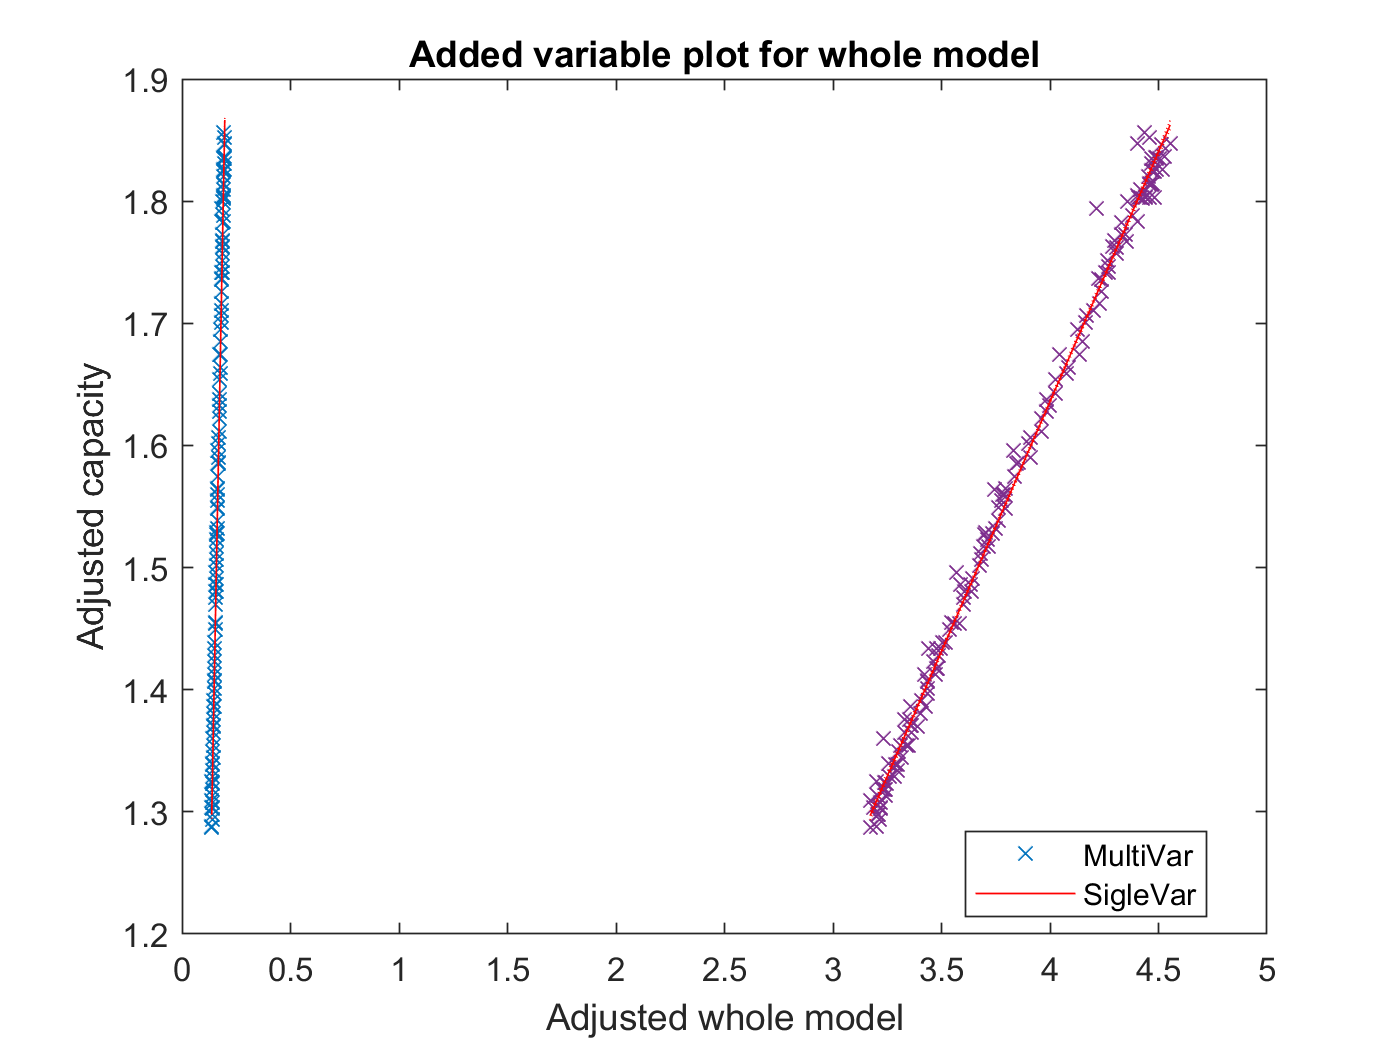


%% plot - model
figure
plot(mdl5)
hold on 
plot(mdlSingleX5)
hold off
legend('MultiVar','SigleVar')

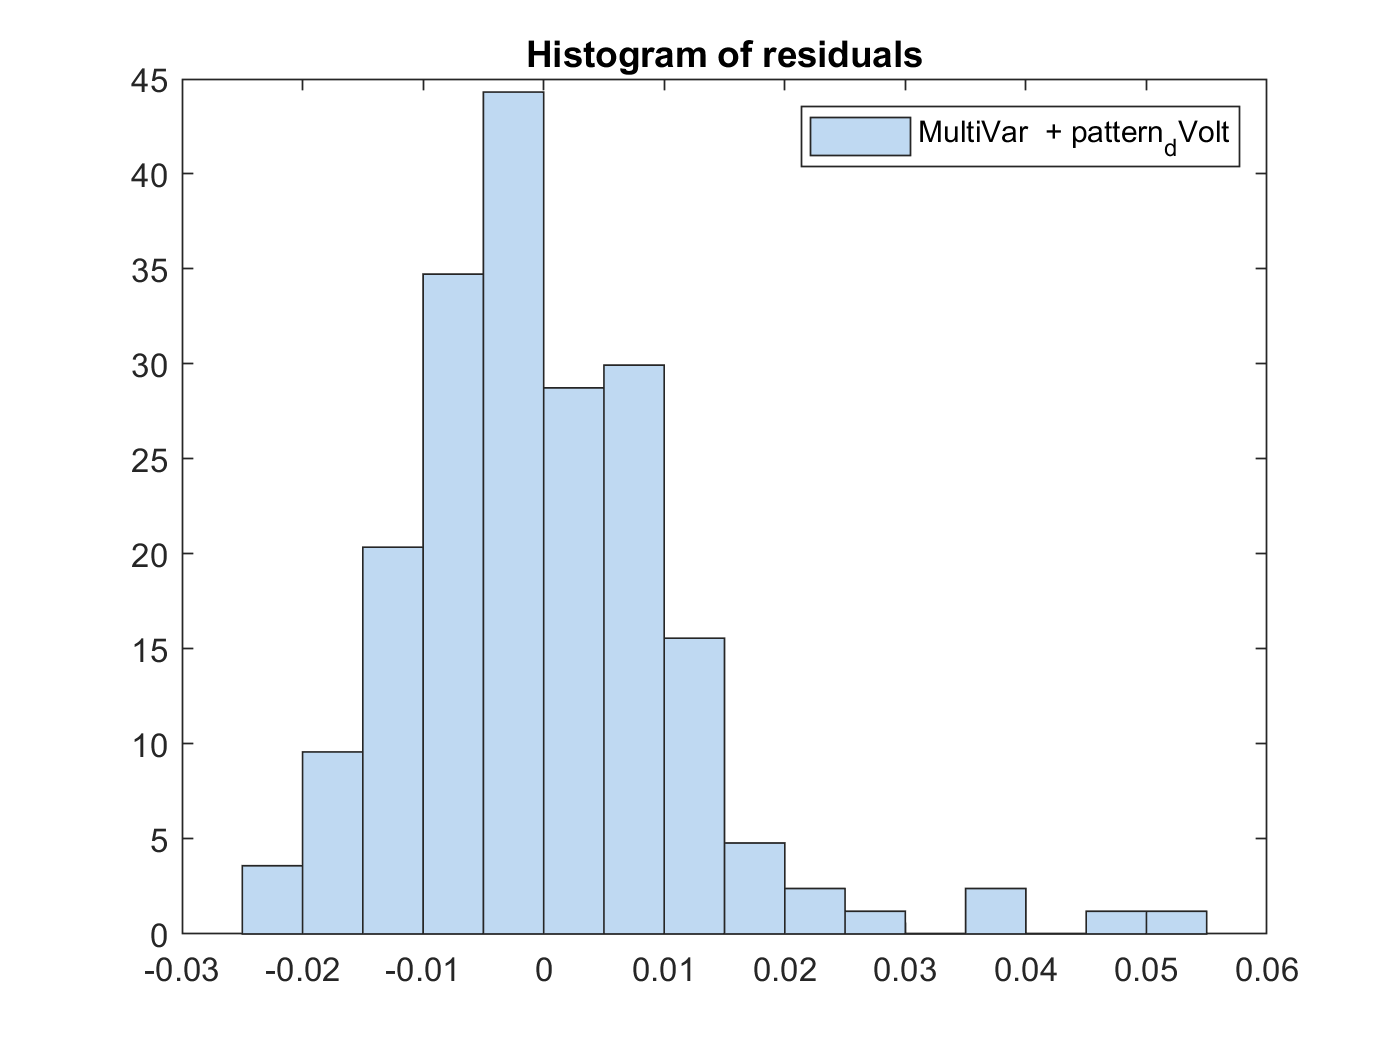



%% plot - residuals 
plotResiduals(mdl5)
legend('MultiVar  + pattern_dVolt')

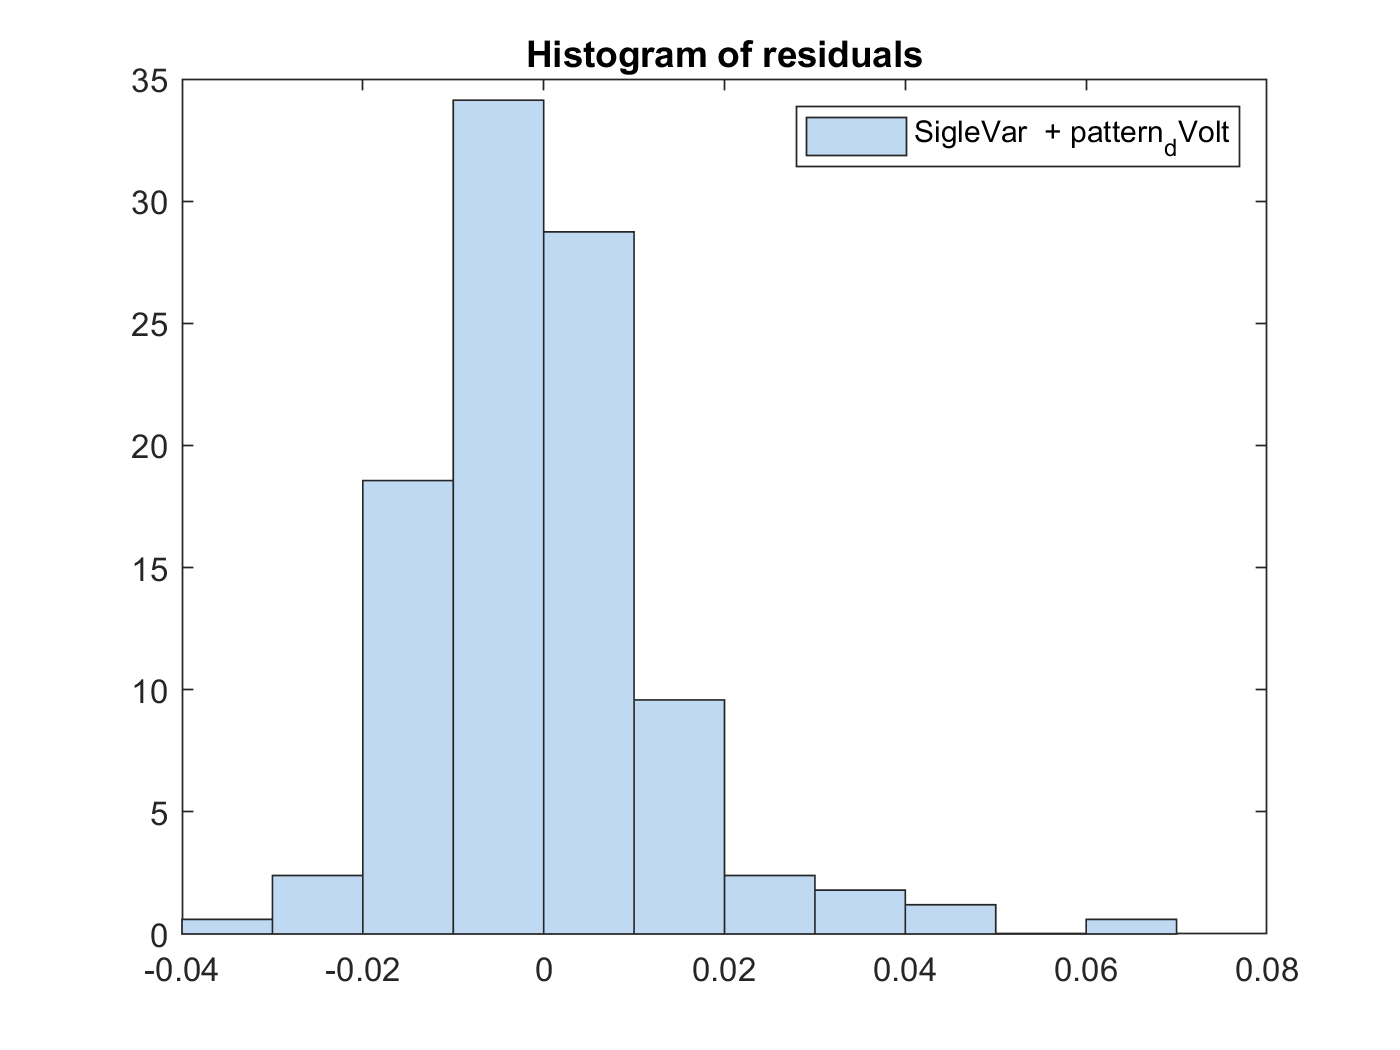

figure
plotResiduals(mdlSingleX5)
legend('SigleVar  + pattern_dVolt')

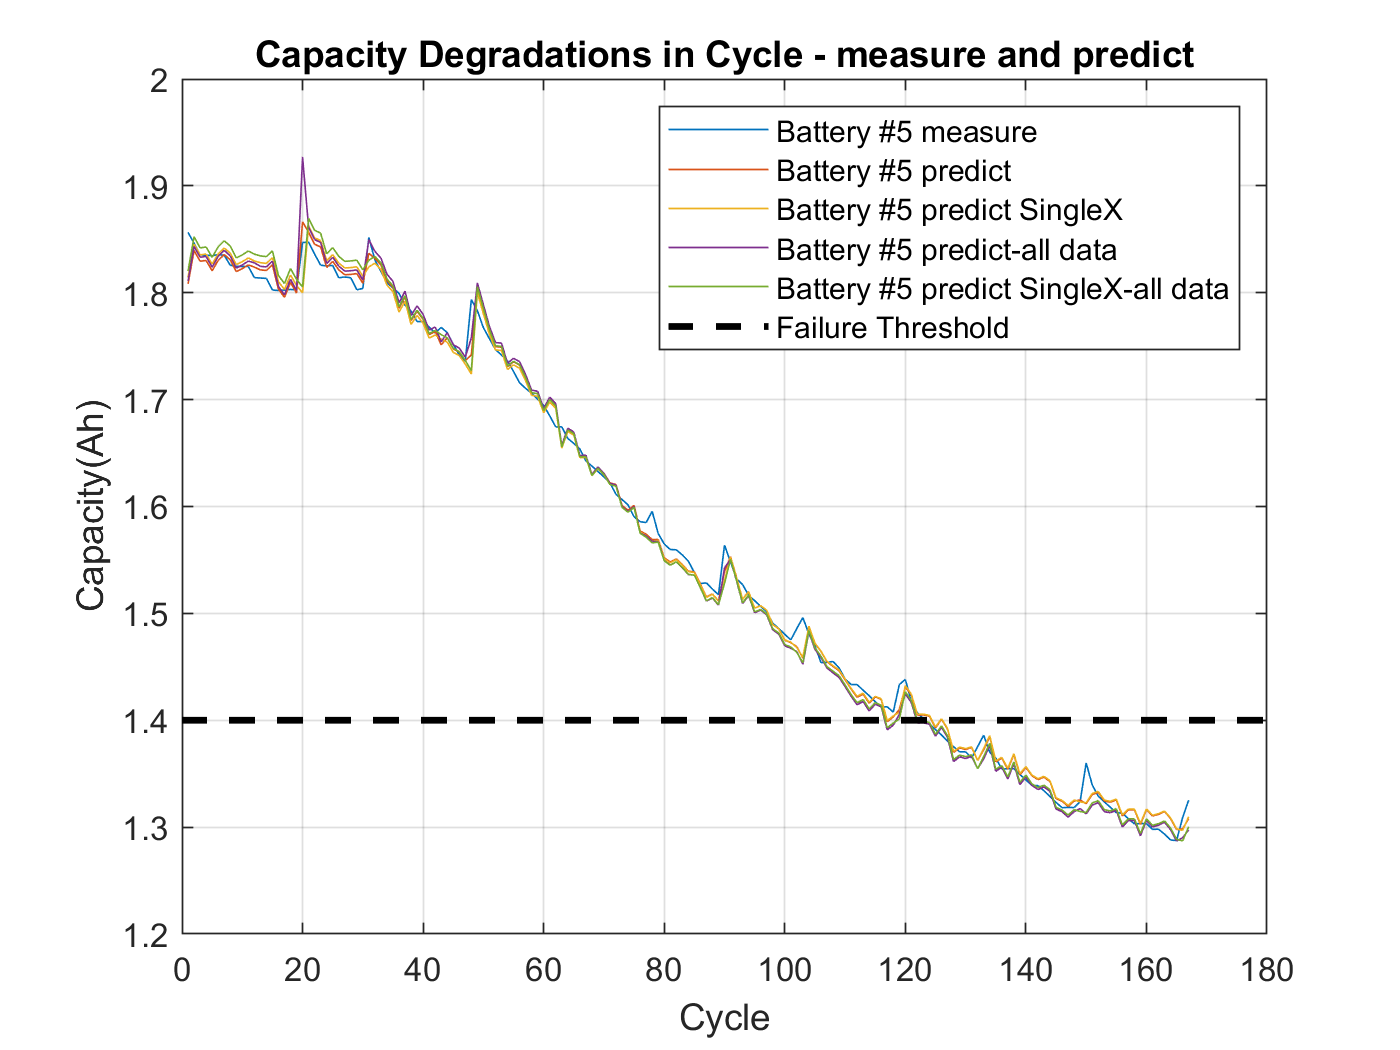

figure


%% plot - hat 
figure
plot(capacity5), hold on, plot(capacityHat5),plot(capacitySingleXHat5),plot(capacityHat),plot(capacitySingleXHat)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 measure', 'Battery #5 predict', 'Battery #5 predict SingleX','Battery #5 predict-all data', 'Battery #5 predict SingleX-all data','Failure Threshold')
title('Capacity Degradations in Cycle - measure and predict')

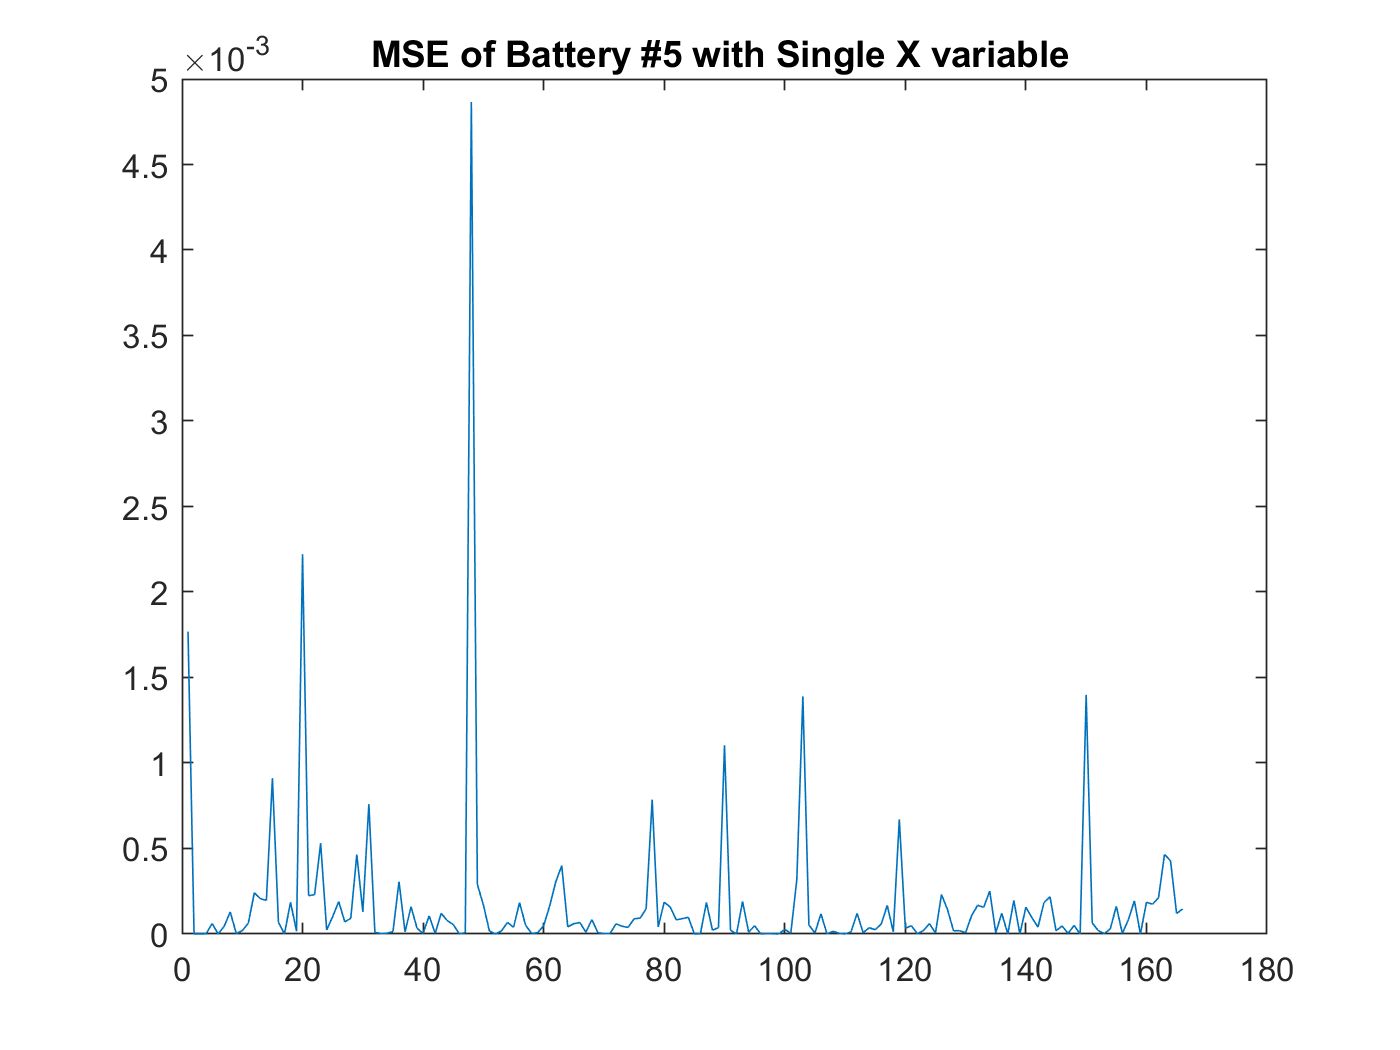


%%

% https://kr.mathworks.com/matlabcentral/answers/4064-rmse-root-mean-square-error
% https://kr.mathworks.com/matlabcentral/answers/234047-plot-mean-square-error

%%
% https://kr.mathworks.com/matlabcentral/answers/26944-plotting-rmse
% not works
%{
dt = 0.1;
k = length(capacity5);
capacityT5 = capacity5';
capacitySingleXHatT5 = capacitySingleXHat5';
err(k)=sqrt(sum(capacityT5(1:k,1)-capacitySingleXHatT5(1:k,1))^2/k);
t(k) = dt*k;  %simulation time, where dt is time for one increment of loop
%outside of loop:
figure
plot(err,t)
title('RMSE of Battery #5 with Single X variable ')
%}


%%
N = length(capacity5);
for i = 1:N-1
    mse_var(i) = mean((capacity5(i)-capacitySingleXHat5(i)).^2);
end
figure
plot(abs(mse_var));
title('MSE of Battery #5 with Single X variable ')


%% summary
% https://kr.mathworks.com/help/stats/linearmodel.html
anova(mdl5,'summary')

ans = 3×5 table
                 SumSq     DF       MeanSq        F        pValue   
                _______    ___    __________    _____    ___________

    Total        6.0538    166      0.036469                        
    Model        6.0307      3        2.0102    14191    7.8162e-197
    Residual    0.02309    163    0.00014166                        


anova(mdlSingleX5,'summary')

ans = 3×5 table
                 SumSq      DF       MeanSq        F        pValue   
                ________    ___    __________    _____    ___________

    Total         6.0538    166      0.036469                        
    Model         6.0241      1        6.0241    33450    1.9809e-192
    Residual    0.029715    165    0.00018009                        



mdl5.MSE

ans = 1.4166e-04

mdl5.RMSE % 0.0131

ans = 0.0119

mdl5.SSE

ans = 0.0231

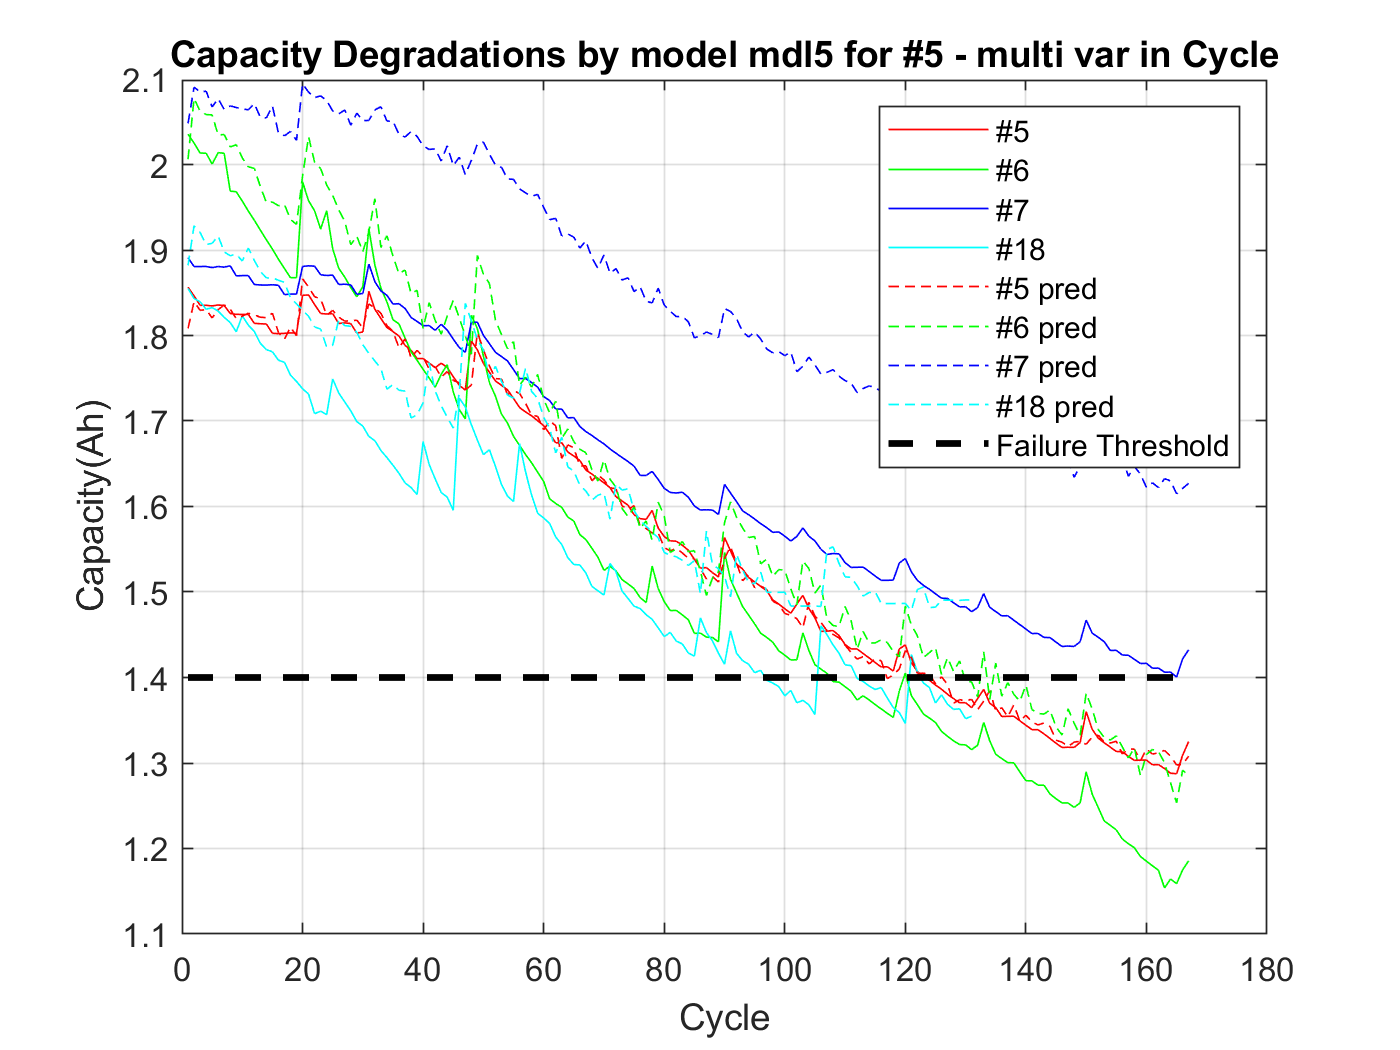

%% model mdl5 from battery 5 - predict other battery
pred6_by_mdl5 = predict(mdl5,regression_table6(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}));
pred7_by_mdl5 = predict(mdl5,regression_table7(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}));
pred18_by_mdl5 = predict(mdl5,regression_table18(:,{'restTime','cTempMaxDtAdj','ohm','pattern_dVolt'}));

%% plot
cycle_number = length(capacity5);

figure
plot(capacity5,'r'), hold on, plot(capacity6,'g'), plot(capacity7,'b'), plot(capacity18,'c')
plot(capacityHat5,'r--'), hold on, plot(pred6_by_mdl5,'g--'), plot(pred7_by_mdl5,'b--'), plot(pred18_by_mdl5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdl5 for #5 - multi var in Cycle')

5+6, 5-6,6-5 

평가 5-6 <= mdl5, mdl6 ,mdl5-6, mdl6-5,mdl 5,6 

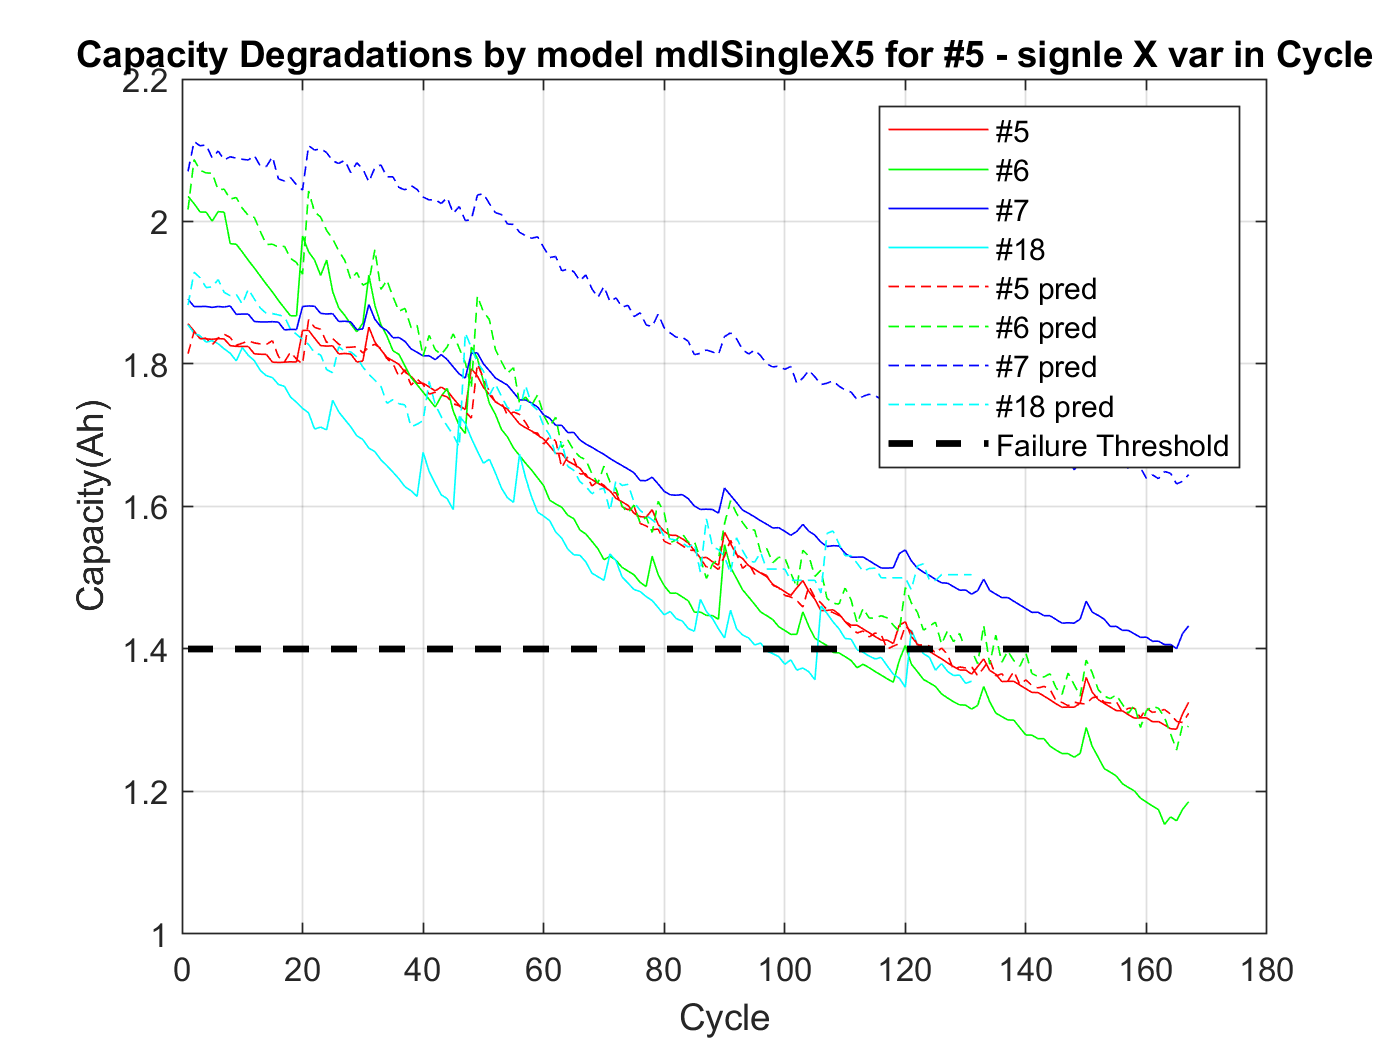

%% model from battery 5 - predict other battery
pred6_by_mdlSingleX5 = predict(mdlSingleX5,regression_table6(:,{'cTempMaxDtAdj','pattern_dVolt'}));
pred7_by_mdlSingleX5 = predict(mdlSingleX5,regression_table7(:,{'cTempMaxDtAdj','pattern_dVolt'}));
pred18_by_mdlSingleX5 = predict(mdlSingleX5,regression_table18(:,{'cTempMaxDtAdj','pattern_dVolt'}));

%% plot
cycle_number = length(capacity5);

figure
plot(capacity5,'r'), hold on, plot(capacity6,'g'), plot(capacity7,'b'), plot(capacity18,'c')
plot(capacitySingleXHat5,'r--'), hold on, plot(pred6_by_mdlSingleX5,'g--'), plot(pred7_by_mdlSingleX5,'b--'), plot(pred18_by_mdlSingleX5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdlSingleX5 for #5 - signle X var in Cycle')




% 18 번 6번은 잘 적용이 안되고 특히 18번은 오류가 많다.
% 아무래도 cTempMaxDtAdj 값이 해당 배터리에서 적용이 잘 안되는 것 같다.



% https://kr.mathworks.com/matlabcentral/answers/386493-rmse-between-two-variables
mdl5.RMSE

ans = 0.0119

mdl6.RMSE

ans = 0.0218

mdl7.RMSE

ans = 0.0098

mdl18.RMSE

ans = 0.0175


RMSE_5 = sqrt(mean(( capacity5 - capacityHat5 ).^2))

RMSE_5 = 0.0118

RMSE_6 = sqrt(mean(( capacity6 - capacityHat6 ).^2))

RMSE_6 = 0.0216

RMSE_7 = sqrt(mean(( capacity7 - capacityHat7 ).^2))

RMSE_7 = 0.0097

RMSE_18 = sqrt(mean(( capacity18 - capacityHat18 ).^2))

RMSE_18 = 0.0172


RMSE_5_by_mdl5 = sqrt(mean(( capacity5 - capacityHat5 ).^2))

RMSE_5_by_mdl5 = 0.0118

RMSE_6_by_mdl5 = sqrt(mean(( capacity6 - pred6_by_mdl5' ).^2))

RMSE_6_by_mdl5 = 0.0835

RMSE_7_by_mdl5 = sqrt(mean(( capacity7 - pred7_by_mdl5' ).^2))

RMSE_7_by_mdl5 = 0.2079

RMSE_18_by_mdl5 = sqrt(mean(( capacity18 - pred18_by_mdl5' ).^2))

RMSE_18_by_mdl5 = 0.1014


mdlSingleX5.RMSE

ans = 0.0134

mdlSingleX6.RMSE

ans = 0.0255

mdlSingleX7.RMSE

ans = 0.0114

mdlSingleX18.RMSE

ans = 0.0263

% https://kr.mathworks.com/matlabcentral/answers/286146-why-rmse-obtained-by-fitlm-in-matlab-does-not-match-with-rmse-calculated-in-excel
% As you can see, dividing by the degrees of freedom is what fitlm must be doing.
% sqrt(sum((y - lm.predict(x)).^2/100)) 
% sqrt(sum((y - lm.predict(x)).^2/100))  -> dividing by the degrees of freedom
RMSE_SingleX_5 = sqrt(mean(( capacity5 - capacitySingleXHat5 ).^2))

RMSE_SingleX_5 = 0.0133

RMSE_SingleX_6 = sqrt(mean(( capacity6 - capacitySingleXHat6 ).^2))

RMSE_SingleX_6 = 0.0253

RMSE_SingleX_7 = sqrt(mean(( capacity7 - capacitySingleXHat7 ).^2))

RMSE_SingleX_7 = 0.0113

RMSE_SingleX_18 = sqrt(mean(( capacity18 - capacitySingleXHat18 ).^2))

RMSE_SingleX_18 = 0.0260


RMSE_5_by_mdlSingleX5 = sqrt(mean(( capacity5 - capacitySingleXHat5 ).^2))

RMSE_5_by_mdlSingleX5 = 0.0133

RMSE_6_by_mdlSingleX5 = sqrt(mean(( capacity6 - pred6_by_mdlSingleX5' ).^2))

RMSE_6_by_mdlSingleX5 = 0.0872

RMSE_7_by_mdlSingleX5 = sqrt(mean(( capacity7 - pred7_by_mdlSingleX5' ).^2))

RMSE_7_by_mdlSingleX5 = 0.2239

RMSE_18_by_mdlSingleX5 = sqrt(mean(( capacity18 - pred18_by_mdlSingleX5' ).^2))

RMSE_18_by_mdlSingleX5 = 0.1106


%% ARIMA 
% https://www.kaggle.com/sumi25/understand-arima-and-tune-p-d-q
% https://machinelearningmastery.com/arima-for-time-series-forecasting-with-python/

